# This exercise is to forecast volatility via different methods, campared with actual volatilities measured by high-frequency realised volatility

Out-of-sample forecasts are from 2019-5-20 to 2022-5-19. Rolling estimation window size is 750 and forecast one-day ahead.

The difference between "exercise_VolForecastRV20220807.mlx" is this mlx mix normal and t-distributed innovation. 

The difference between "exercise_VolForecastRV20220805.mlx" is this mlx is for DEBUG, especially for NIKKIE in "exercise_VolForecastRV20220805.mlx" performs super badly, especially CP-RSGARCH and CP-RSGARCH-I. We separate GARCH, GJR, RSGARCH and HAR into different functions to calculate corresponding volatility, VolFcst_GARCH, VolFcst_GJR, VolFcst_RSGARCH and VolFcst_HAR. Then you have to use Save_VolFcst_to_Mat to save results.

clear,clc
addpath("Functions/")
tic
Read_Name='SP500_0608.xlsx';
Time_Outsample=[2021,05,18;2022,05,18];
results_GARCH=VolFcst_GARCH(Read_Name,Time_Outsample);
rv=get_rv(Read_Name,Time_Outsample);
results_CPGARCH=VolFcst_CPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGARCH: i=1
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
CPGARCH: i=2
CPGARCH: i=3
CPGARCH: i=4
CPGARCH: i=5
CPGARCH: i=6
CPGARCH: i=7
CPGARCH: i=8
CPGARCH: i=9
CPGARCH: i=10
CPGARCH: i=11
CPGARCH: i=12
CPGARCH: i=13
CPGARCH: i=14
CPGARCH: i=15
CPGARCH: i=16
CPGARCH: i=17
CPGARCH: i=18
CPGARCH: i=19
CPGARCH: i=20
CPGARCH: i=21
CPGARCH: i=22
CPGARCH: i=23
CPGARCH: i=24
CPGARCH: i=25
CPGARCH: i=26
CPGARCH: i=27
CPGARCH: i=28
CPGARCH: i=29
CPGARCH: i=30
CPGARCH: i=31
CPGARCH: i=32
CPGARCH: i=33
CPGARCH: i=34
CPGARCH: i=35
CPGARCH: i=36
CPGARCH: i=37
CPGARCH: i=38
CPGARCH: i=39
CPGARCH: i=40
CPGARCH: i=41
CPGARCH: i=42
CPGARCH: i=43
CPGARCH: i=44
CPGARCH: i=45
CPGARCH: i=46
CPGARCH: i=47
CPGARCH: i=48
CPGARCH: i=49
CPGARCH: i=50
CPGARCH: i=51
CPGARCH: i=52
CPGARCH: i=53
CPGARCH: i=54
CPGARCH: i=55
CPGARCH: i=56
CPGARCH: i=57
CPGARCH: i=58
CPGARCH: i=59
CPGARCH: i=60
CPGARCH: i=61
CPGARCH: i=62
CPGARCH: i=63
CPGARCH: 

results_ICPGARCH=VolFcst_ICPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGARCH: i=1
ICPGARCH: i=2
ICPGARCH: i=3
ICPGARCH: i=4
ICPGARCH: i=5
ICPGARCH: i=6
ICPGARCH: i=7
ICPGARCH: i=8
ICPGARCH: i=9
ICPGARCH: i=10
ICPGARCH: i=11
ICPGARCH: i=12
ICPGARCH: i=13
ICPGARCH: i=14
ICPGARCH: i=15
ICPGARCH: i=16
ICPGARCH: i=17
ICPGARCH: i=18
ICPGARCH: i=19
ICPGARCH: i=20
ICPGARCH: i=21
ICPGARCH: i=22
ICPGARCH: i=23
ICPGARCH: i=24
ICPGARCH: i=25
ICPGARCH: i=26
ICPGARCH: i=27
ICPGARCH: i=28
ICPGARCH: i=29
ICPGARCH: i=30
ICPGARCH: i=31
ICPGARCH: i=32
ICPGARCH: i=33
ICPGARCH: i=34
ICPGARCH: i=35
ICPGARCH: i=36
ICPGARCH: i=37
ICPGARCH: i=38
ICPGARCH: i=39
ICPGARCH: i=40
ICPGARCH: i=41
ICPGARCH: i=42
ICPGARCH: i=43
ICPGARCH: i=44
ICPGARCH: i=45
ICPGARCH: i=46
ICPGARCH: i=47
ICPGARCH: i=48
ICPGARCH: i=49
ICPGARCH: i=50
ICPGARCH: i=51
ICPGARCH: i=52
ICPGARCH: i=53
ICPGARCH: i=54
ICPGARCH: i=55
ICPGARCH: i=56
ICPGARCH: i=57
ICPGARCH: i=58
ICPGARCH: i=59
ICPGARCH: i=60
ICPGARCH: i=61
ICPGARCH: i=62
ICPGARCH: i=63
ICPGARCH: i=64
ICPGARCH: i=65
ICPGARCH: i=66
ICPGARCH: i=67
ICPG

results_GJR=VolFcst_GJR(Read_Name,Time_Outsample);

GJR: i=1
GJR: i=2
GJR: i=3
GJR: i=4
GJR: i=5
GJR: i=6
GJR: i=7
GJR: i=8
GJR: i=9
GJR: i=10
GJR: i=11
GJR: i=12
GJR: i=13
GJR: i=14
GJR: i=15
GJR: i=16
GJR: i=17
GJR: i=18
GJR: i=19
GJR: i=20
GJR: i=21
GJR: i=22
GJR: i=23
GJR: i=24
GJR: i=25
GJR: i=26
GJR: i=27
GJR: i=28
GJR: i=29
GJR: i=30
GJR: i=31
GJR: i=32
GJR: i=33
GJR: i=34
GJR: i=35
GJR: i=36
GJR: i=37
GJR: i=38
GJR: i=39
GJR: i=40
GJR: i=41
GJR: i=42
GJR: i=43
GJR: i=44
GJR: i=45
GJR: i=46
GJR: i=47
GJR: i=48
GJR: i=49
GJR: i=50
GJR: i=51
GJR: i=52
GJR: i=53
GJR: i=54
GJR: i=55
GJR: i=56
GJR: i=57
GJR: i=58
GJR: i=59
GJR: i=60
GJR: i=61
GJR: i=62
GJR: i=63
GJR: i=64
GJR: i=65
GJR: i=66
GJR: i=67
GJR: i=68
GJR: i=69
GJR: i=70
GJR: i=71
GJR: i=72
GJR: i=73
GJR: i=74
GJR: i=75
GJR: i=76
GJR: i=77
GJR: i=78
GJR: i=79
GJR: i=80
GJR: i=81
GJR: i=82
GJR: i=83
GJR: i=84
GJR: i=85
GJR: i=86
GJR: i=87
GJR: i=88
GJR: i=89
GJR: i=90
GJR: i=91
GJR: i=92
GJR: i=93
GJR: i=94
GJR: i=95
GJR: i=96
GJR: i=97
GJR: i=98
GJR: i=99
GJR: i=100
GJR: i=1

results_CPGJR=VolFcst_CPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGJR: i=1
CPGJR: i=2
CPGJR: i=3
CPGJR: i=4
CPGJR: i=5
CPGJR: i=6
CPGJR: i=7
CPGJR: i=8
CPGJR: i=9
CPGJR: i=10
CPGJR: i=11
CPGJR: i=12
CPGJR: i=13
CPGJR: i=14
CPGJR: i=15
CPGJR: i=16
CPGJR: i=17
CPGJR: i=18
CPGJR: i=19
CPGJR: i=20
CPGJR: i=21
CPGJR: i=22
CPGJR: i=23
CPGJR: i=24
CPGJR: i=25
CPGJR: i=26
CPGJR: i=27
CPGJR: i=28
CPGJR: i=29
CPGJR: i=30
CPGJR: i=31
CPGJR: i=32
CPGJR: i=33
CPGJR: i=34
CPGJR: i=35
CPGJR: i=36
CPGJR: i=37
CPGJR: i=38
CPGJR: i=39
CPGJR: i=40
CPGJR: i=41
CPGJR: i=42
CPGJR: i=43
CPGJR: i=44
CPGJR: i=45
CPGJR: i=46
CPGJR: i=47
CPGJR: i=48
CPGJR: i=49
CPGJR: i=50
CPGJR: i=51
CPGJR: i=52
CPGJR: i=53
CPGJR: i=54
CPGJR: i=55
CPGJR: i=56
CPGJR: i=57
CPGJR: i=58
CPGJR: i=59
CPGJR: i=60
CPGJR: i=61
CPGJR: i=62
CPGJR: i=63
CPGJR: i=64
CPGJR: i=65
CPGJR: i=66
CPGJR: i=67
CPGJR: i=68
CPGJR: i=69
CPGJR: i=70
CPGJR: i=71
CPGJR: i=72
CPGJR: i=73
CPGJR: i=74
CPGJR: i=75
CPGJR: i=76
CPGJR: i=77
CPGJR: i=78
CPGJR: i=79
CPGJR: i=80
CPGJR: i=81
CPGJR: i=82
CPGJR: i=83
CPGJR: i=84
C

results_ICPGJR=VolFcst_ICPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGJR: i=1
ICPGJR: i=2
ICPGJR: i=3
ICPGJR: i=4
ICPGJR: i=5
ICPGJR: i=6
ICPGJR: i=7
ICPGJR: i=8
ICPGJR: i=9
ICPGJR: i=10
ICPGJR: i=11
ICPGJR: i=12
ICPGJR: i=13
ICPGJR: i=14
ICPGJR: i=15
ICPGJR: i=16
ICPGJR: i=17
ICPGJR: i=18
ICPGJR: i=19
ICPGJR: i=20
ICPGJR: i=21
ICPGJR: i=22
ICPGJR: i=23
ICPGJR: i=24
ICPGJR: i=25
ICPGJR: i=26
ICPGJR: i=27
ICPGJR: i=28
ICPGJR: i=29
ICPGJR: i=30
ICPGJR: i=31
ICPGJR: i=32
ICPGJR: i=33
ICPGJR: i=34
ICPGJR: i=35
ICPGJR: i=36
ICPGJR: i=37
ICPGJR: i=38
ICPGJR: i=39
ICPGJR: i=40
ICPGJR: i=41
ICPGJR: i=42
ICPGJR: i=43
ICPGJR: i=44
ICPGJR: i=45
ICPGJR: i=46
ICPGJR: i=47
ICPGJR: i=48
ICPGJR: i=49
ICPGJR: i=50
ICPGJR: i=51
ICPGJR: i=52
ICPGJR: i=53
ICPGJR: i=54
ICPGJR: i=55
ICPGJR: i=56
ICPGJR: i=57
ICPGJR: i=58
ICPGJR: i=59
ICPGJR: i=60
ICPGJR: i=61
ICPGJR: i=62
ICPGJR: i=63
ICPGJR: i=64
ICPGJR: i=65
ICPGJR: i=66
ICPGJR: i=67
ICPGJR: i=68
ICPGJR: i=69
ICPGJR: i=70
ICPGJR: i=71
ICPGJR: i=72
ICPGJR: i=73
ICPGJR: i=74
ICPGJR: i=75
ICPGJR: i=76
ICPGJR: i=77
ICPGJR: 

results_RSGARCH=VolFcst_RSGARCH(Read_Name,Time_Outsample);

RSGARCH: i=1
RSGARCH: i=2
RSGARCH: i=3
RSGARCH: i=4
RSGARCH: i=5
RSGARCH: i=6
RSGARCH: i=7
RSGARCH: i=8
RSGARCH: i=9
RSGARCH: i=10
RSGARCH: i=11
RSGARCH: i=12
RSGARCH: i=13
RSGARCH: i=14
RSGARCH: i=15
RSGARCH: i=16
RSGARCH: i=17
RSGARCH: i=18
RSGARCH: i=19
RSGARCH: i=20
RSGARCH: i=21
RSGARCH: i=22
RSGARCH: i=23
RSGARCH: i=24
RSGARCH: i=25
RSGARCH: i=26
RSGARCH: i=27
RSGARCH: i=28
RSGARCH: i=29
RSGARCH: i=30
RSGARCH: i=31
RSGARCH: i=32
RSGARCH: i=33
RSGARCH: i=34
RSGARCH: i=35
RSGARCH: i=36
RSGARCH: i=37
RSGARCH: i=38
RSGARCH: i=39
RSGARCH: i=40
RSGARCH: i=41
RSGARCH: i=42
RSGARCH: i=43
RSGARCH: i=44
RSGARCH: i=45
RSGARCH: i=46
RSGARCH: i=47
RSGARCH: i=48
RSGARCH: i=49
RSGARCH: i=50
RSGARCH: i=51
RSGARCH: i=52
RSGARCH: i=53
RSGARCH: i=54
RSGARCH: i=55
RSGARCH: i=56
RSGARCH: i=57
RSGARCH: i=58
RSGARCH: i=59
RSGARCH: i=60
RSGARCH: i=61
RSGARCH: i=62
RSGARCH: i=63
RSGARCH: i=64
RSGARCH: i=65
RSGARCH: i=66
RSGARCH: i=67
RSGARCH: i=68
RSGARCH: i=69
RSGARCH: i=70
RSGARCH: i=71
RSGARCH: i=72
R

results_CPRSGARCH=VolFcst_CPRSGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPRSGARCH: i=34
CPRSGARCH: i=35
CPRSGARCH: i=36
CPRSGARCH: i=37
CPRSGARCH: i=38
CPRSGARCH: i=39
CPRSGARCH: i=40
CPRSGARCH: i=41
CPRSGARCH: i=42
CPRSGARCH: i=43
CPRSGARCH: i=44
CPRSGARCH: i=45
CPRSGARCH: i=46
CPRSGARCH: i=47
CPRSGARCH: i=48
CPRSGARCH: i=49
CPRSGARCH: i=50
CPRSGARCH: i=51
CPRSGARCH: i=52
CPRSGARCH: i=53
CPRSGARCH: i=54
CPRSGARCH: i=55
CPRSGARCH: i=56
CPRSGARCH: i=57
CPRSGARCH: i=58
CPRSGARCH: i=59
CPRSGARCH: i=60
CPRSGARCH: i=61
CPRSGARCH: i=62
CPRSGARCH: i=63
CPRSGARCH: i=64
CPRSGARCH: i=65
CPRSGARCH: i=66
CPRSGARCH: i=67
CPRSGARCH: i=68
CPRSGARCH: i=69
CPRSGARCH: i=70
CPRSGARCH: i=71
CPRSGARCH: i=72
CPRSGARCH: i=73
CPRSGARCH: i=74
CPRSGARCH: i=75
CPRSGARCH: i=76
CPRSGARCH: i=77
CPRSGARCH: i=78
CPRSGARCH: i=79
CPRSGARCH: i=80
CPRSGARCH: i=81
CPRSGARCH: i=82
CPRSGARCH: i=83
CPRSGARCH: i=84
CPRSGARCH: i=85
CPRSGARCH: i=86
CPRSGARCH: i=87
CPRSGARCH: i=88
CPRSGARCH: i=89
CPRSGARCH: i=90
CPRSGARCH: i=91
CPRSGARCH: i=92
CPRSGARCH: i=93
CPRSGARCH: i=94
CPRSGARCH: i=95
CPRSGARC

results_ICPRSGARCH=VolFcst_ICPRSGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPRSGARCH: i=1


ICPRSGARCH: i=2


ICPRSGARCH: i=3


ICPRSGARCH: i=4


ICPRSGARCH: i=5


ICPRSGARCH: i=6


ICPRSGARCH: i=7


ICPRSGARCH: i=8


ICPRSGARCH: i=9


ICPRSGARCH: i=10


ICPRSGARCH: i=11


ICPRSGARCH: i=12


ICPRSGARCH: i=13


ICPRSGARCH: i=14


ICPRSGARCH: i=15


ICPRSGARCH: i=16


ICPRSGARCH: i=17


ICPRSGARCH: i=18


ICPRSGARCH: i=19


ICPRSGARCH: i=20


ICPRSGARCH: i=21


ICPRSGARCH: i=22


ICPRSGARCH: i=23


ICPRSGARCH: i=24


ICPRSGARCH: i=25


ICPRSGARCH: i=26


ICPRSGARCH: i=27


ICPRSGARCH: i=28


ICPRSGARCH: i=29


ICPRSGARCH: i=30


ICPRSGARCH: i=31


ICPRSGARCH: i=32


ICPRSGARCH: i=33


ICPRSGARCH: i=34


ICPRSGARCH: i=35


ICPRSGARCH: i=36


ICPRSGARCH: i=37


ICPRSGARCH: i=38


ICPRSGARCH: i=39


ICPRSGARCH: i=40


ICPRSGARCH: i=41


ICPRSGARCH: i=42


ICPRSGARCH: i=43


ICPRSGARCH: i=44


ICPRSGARCH: i=45


ICPRSGARCH: i=46


ICPRSGARCH: i=47


ICPRSGARCH: i=48


ICPRSGARCH: i=49


ICPRSGARCH: i=50


ICPRSGARCH: i=51


ICPRSGARCH: i=52


ICPRSGARCH: i=53


ICPRSGARCH: i=54


ICPRSGARCH: i=55


ICPRSGARCH: i=56


ICPRSGARCH: i=57


ICPRSGARCH: i=58


ICPRSGARCH: i=59


ICPRSGARCH: i=60


ICPRSGARCH: i=61


ICPRSGARCH: i=62


ICPRSGARCH: i=63


ICPRSGARCH: i=64


ICPRSGARCH: i=65


ICPRSGARCH: i=66


ICPRSGARCH: i=67


ICPRSGARCH: i=68


ICPRSGARCH: i=69


ICPRSGARCH: i=70


ICPRSGARCH: i=71


ICPRSGARCH: i=72


ICPRSGARCH: i=73


ICPRSGARCH: i=74


ICPRSGARCH: i=75


ICPRSGARCH: i=76


ICPRSGARCH: i=77


ICPRSGARCH: i=78


ICPRSGARCH: i=79


ICPRSGARCH: i=80


ICPRSGARCH: i=81


ICPRSGARCH: i=82


ICPRSGARCH: i=83


ICPRSGARCH: i=84


ICPRSGARCH: i=85


ICPRSGARCH: i=86


ICPRSGARCH: i=87


ICPRSGARCH: i=88


ICPRSGARCH: i=89


ICPRSGARCH: i=90


ICPRSGARCH: i=91


ICPRSGARCH: i=92


ICPRSGARCH: i=93


ICPRSGARCH: i=94


ICPRSGARCH: i=95


ICPRSGARCH: i=96


ICPRSGARCH: i=97


ICPRSGARCH: i=98


ICPRSGARCH: i=119


ICPRSGARCH: i=120


ICPRSGARCH: i=121


ICPRSGARCH: i=122


ICPRSGARCH: i=123


ICPRSGARCH: i=124


ICPRSGARCH: i=125


ICPRSGARCH: i=126


ICPRSGARCH: i=127


ICPRSGARCH: i=128


ICPRSGARCH: i=129


ICPRSGARCH: i=130


ICPRSGARCH: i=131


ICPRSGARCH: i=132


ICPRSGARCH: i=133


ICPRSGARCH: i=134


ICPRSGARCH: i=135


ICPRSGARCH: i=136


ICPRSGARCH: i=137


ICPRSGARCH: i=138


ICPRSGARCH: i=139


ICPRSGARCH: i=140


ICPRSGARCH: i=141


ICPRSGARCH: i=142


ICPRSGARCH: i=143


ICPRSGARCH: i=144


ICPRSGARCH: i=145


ICPRSGARCH: i=146


ICPRSGARCH: i=147


ICPRSGARCH: i=148


ICPRSGARCH: i=149


ICPRSGARCH: i=150


ICPRSGARCH: i=151


ICPRSGARCH: i=152


ICPRSGARCH: i=153


ICPRSGARCH: i=154


ICPRSGARCH: i=155


ICPRSGARCH: i=156


ICPRSGARCH: i=157


ICPRSGARCH: i=158


ICPRSGARCH: i=159


ICPRSGARCH: i=160


ICPRSGARCH: i=161


ICPRSGARCH: i=162


ICPRSGARCH: i=163


ICPRSGARCH: i=164


ICPRSGARCH: i=165


ICPRSGARCH: i=166


ICPRSGARCH: i=167


ICPRSGARCH: i=168


ICPRSGARCH: i=169


ICPRSGARCH: i=170


ICPRSGARCH: i=171


ICPRSGARCH: i=172


ICPRSGARCH: i=173


ICPRSGARCH: i=174


ICPRSGARCH: i=175


ICPRSGARCH: i=176


ICPRSGARCH: i=177


ICPRSGARCH: i=178


ICPRSGARCH: i=179


ICPRSGARCH: i=180


ICPRSGARCH: i=181


ICPRSGARCH: i=182


ICPRSGARCH: i=183


ICPRSGARCH: i=184


ICPRSGARCH: i=185


ICPRSGARCH: i=186


ICPRSGARCH: i=187


ICPRSGARCH: i=188


ICPRSGARCH: i=189


ICPRSGARCH: i=190


ICPRSGARCH: i=191


ICPRSGARCH: i=192


ICPRSGARCH: i=193


ICPRSGARCH: i=194


ICPRSGARCH: i=195


ICPRSGARCH: i=216


ICPRSGARCH: i=217


ICPRSGARCH: i=218


ICPRSGARCH: i=219


ICPRSGARCH: i=220


ICPRSGARCH: i=221


ICPRSGARCH: i=222


ICPRSGARCH: i=223


ICPRSGARCH: i=224


ICPRSGARCH: i=225


ICPRSGARCH: i=226


ICPRSGARCH: i=227


ICPRSGARCH: i=228


ICPRSGARCH: i=229


ICPRSGARCH: i=230


ICPRSGARCH: i=231


ICPRSGARCH: i=232


ICPRSGARCH: i=233


ICPRSGARCH: i=234


ICPRSGARCH: i=235


ICPRSGARCH: i=236


ICPRSGARCH: i=237


ICPRSGARCH: i=238


ICPRSGARCH: i=239


ICPRSGARCH: i=240


ICPRSGARCH: i=241


ICPRSGARCH: i=242


ICPRSGARCH: i=243


ICPRSGARCH: i=244


ICPRSGARCH: i=245


ICPRSGARCH: i=246


ICPRSGARCH: i=247


ICPRSGARCH: i=248


ICPRSGARCH: i=249


results_HAR=VolFcst_HAR(Read_Name,Time_Outsample);
results_CPHAR=VolFcst_CPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR: i=122
CPHAR: i=123


results_ICPHAR=VolFcst_ICPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR: i=102
ICPHAR: i=176


results_HAR_a=VolFcst_HAR_a(Read_Name,Time_Outsample);
results_CPHAR_a=VolFcst_CPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR-a: i=5
CPHAR-a: i=6
CPHAR-a: i=7
CPHAR-a: i=8
CPHAR-a: i=9
CPHAR-a: i=10
CPHAR-a: i=11
CPHAR-a: i=12
CPHAR-a: i=13
CPHAR-a: i=14
CPHAR-a: i=15
CPHAR-a: i=16
CPHAR-a: i=17
CPHAR-a: i=18
CPHAR-a: i=19
CPHAR-a: i=20
CPHAR-a: i=21
CPHAR-a: i=22
CPHAR-a: i=23
CPHAR-a: i=24
CPHAR-a: i=25
CPHAR-a: i=26
CPHAR-a: i=27
CPHAR-a: i=28
CPHAR-a: i=29
CPHAR-a: i=30
CPHAR-a: i=31
CPHAR-a: i=32
CPHAR-a: i=33
CPHAR-a: i=34
CPHAR-a: i=35
CPHAR-a: i=36
CPHAR-a: i=37
CPHAR-a: i=38
CPHAR-a: i=39
CPHAR-a: i=40
CPHAR-a: i=41
CPHAR-a: i=42
CPHAR-a: i=43
CPHAR-a: i=44
CPHAR-a: i=45
CPHAR-a: i=46
CPHAR-a: i=47
CPHAR-a: i=48
CPHAR-a: i=49
CPHAR-a: i=50
CPHAR-a: i=51
CPHAR-a: i=52
CPHAR-a: i=53
CPHAR-a: i=54
CPHAR-a: i=55
CPHAR-a: i=56
CPHAR-a: i=57
CPHAR-a: i=58
CPHAR-a: i=59
CPHAR-a: i=60
CPHAR-a: i=61
CPHAR-a: i=62
CPHAR-a: i=63
CPHAR-a: i=64
CPHAR-a: i=65
CPHAR-a: i=66
CPHAR-a: i=67
CPHAR-a: i=68
CPHAR-a: i=69
CPHAR-a: i=70
CPHAR-a: i=71
CPHAR-a: i=72
CPHAR-a: i=73
CPHAR-a: i=74
CPHAR-a: i=75
CPHAR-a: i=

results_ICPHAR_a=VolFcst_ICPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR-a: i=1
ICPHAR-a: i=2
ICPHAR-a: i=3
ICPHAR-a: i=4
ICPHAR-a: i=5
ICPHAR-a: i=6
ICPHAR-a: i=7
ICPHAR-a: i=8
ICPHAR-a: i=9
ICPHAR-a: i=10
ICPHAR-a: i=11
ICPHAR-a: i=12
ICPHAR-a: i=13
ICPHAR-a: i=14
ICPHAR-a: i=15
ICPHAR-a: i=16
ICPHAR-a: i=17
ICPHAR-a: i=18
ICPHAR-a: i=19
ICPHAR-a: i=20
ICPHAR-a: i=21
ICPHAR-a: i=22
ICPHAR-a: i=23
ICPHAR-a: i=24
ICPHAR-a: i=25
ICPHAR-a: i=26
ICPHAR-a: i=27
ICPHAR-a: i=28
ICPHAR-a: i=29
ICPHAR-a: i=30
ICPHAR-a: i=31
ICPHAR-a: i=32
ICPHAR-a: i=33
ICPHAR-a: i=34
ICPHAR-a: i=35
ICPHAR-a: i=36
ICPHAR-a: i=37
ICPHAR-a: i=38
ICPHAR-a: i=39
ICPHAR-a: i=40
ICPHAR-a: i=41
ICPHAR-a: i=42
ICPHAR-a: i=43
ICPHAR-a: i=44
ICPHAR-a: i=45
ICPHAR-a: i=46
ICPHAR-a: i=47
ICPHAR-a: i=48
ICPHAR-a: i=49
ICPHAR-a: i=50
ICPHAR-a: i=51
ICPHAR-a: i=52
ICPHAR-a: i=53
ICPHAR-a: i=54
ICPHAR-a: i=55
ICPHAR-a: i=56
ICPHAR-a: i=57
ICPHAR-a: i=58
ICPHAR-a: i=59
ICPHAR-a: i=60
ICPHAR-a: i=61
ICPHAR-a: i=62
ICPHAR-a: i=63
ICPHAR-a: i=64
ICPHAR-a: i=65
ICPHAR-a: i=66
ICPHAR-a: i=67
ICPH

Save forecast volatility

Index_Name = 'SP500';
Working_Date = '20220913';
Window_Size = 750;
results_folder = get_results_folder(Index_Name,Working_Date);
Timeline_outsample = get_datetime_outofsample(Read_Name,Time_Outsample);
Model_Name={'GARCH','CPGARCH','ICPGARCH',...
        'GJR','CPGJR','ICPGJR', ...
        'RSGARCH','CPRSGARCH','ICPRSGARCH',...
        'HAR','CPHAR','ICPHAR',...
        'HAR_a','CPHAR_a','ICPHAR_a'};
for i=1:15
    save([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date],['results_',Model_Name{i}]);
end
Output_Table=table(Timeline_outsample,sqrt(results_GARCH.vf_GARCH),sqrt(results_CPGARCH.vf_CPGARCH),sqrt(results_ICPGARCH.vf_ICPGARCH), ...
    sqrt(results_GJR.vf_GJR),sqrt(results_CPGJR.vf_CPGJR),sqrt(results_ICPGJR.vf_ICPGJR), ...
    sqrt(results_RSGARCH.vf_RSGARCH),sqrt(results_CPRSGARCH.vf_CPRSGARCH),sqrt(results_ICPRSGARCH.vf_ICPRSGARCH), ...
    sqrt(results_HAR.vf_HAR),sqrt(results_CPHAR.vf_CPHAR),sqrt(results_ICPHAR.vf_ICPHAR), ...
    sqrt(results_HAR_a.vf_HAR_a),sqrt(results_CPHAR_a.vf_CPHAR_a),sqrt(results_ICPHAR_a.vf_ICPHAR_a), ...
    'VariableNames',{'Date','vf_GARCH','vf_CPGARCH','vf_ICPGARCH', ...
    'vf_GJR','vf_CPGJR','vf_ICPGJR', ...
    'vf_RSGARCH','vf_CPRSGARCH','vf_ICPRSGARCH', ...
    'vf_HAR','vf_CPHAR','vf_ICPHAR', ...
    'vf_HAR_a','vf_CPHAR_a','vf_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Volatility_Forecast_',Working_Date,'.xlsx']);

Load forecast volatility

for i=1:15
    load([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date]);
end

Volatility forecasts: GARCH, CPGARCH, ICPGARCH,

GJR, CPGJR, ICPGJR, 

RSGARCH, CPRSGARCH, ICPRSGARCH, 

HAR, CPHAR, ICPHAR, HAR-a, CPHAR-a, ICPHAR-a

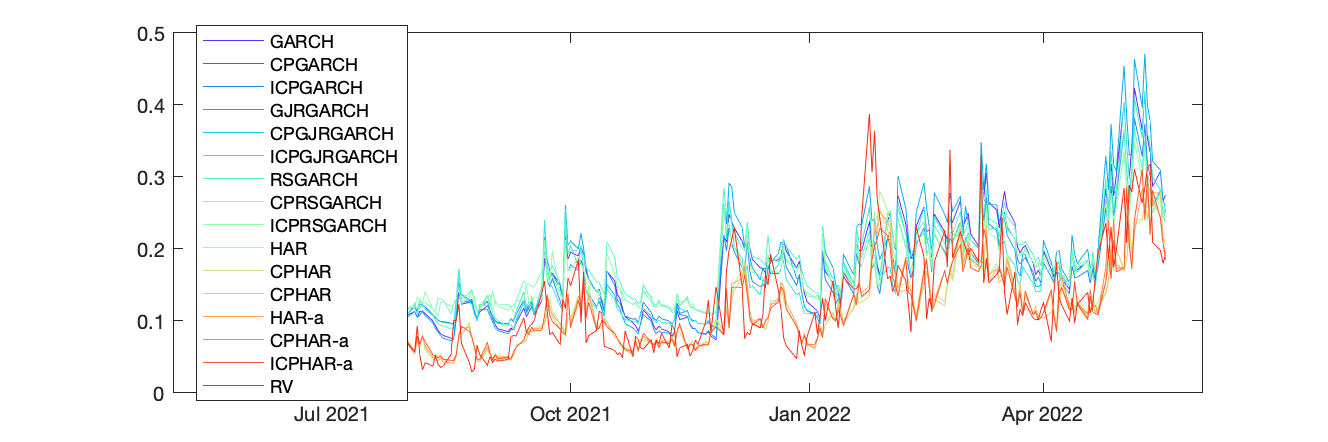

figure;
col=rainbow(16);
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(4,:));
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(5,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(6,:))
plot(Timeline_outsample,sqrt(results_RSGARCH.vf_RSGARCH)*sqrt(250), "Color",col(7,:));
plot(Timeline_outsample,sqrt(results_CPRSGARCH.vf_CPRSGARCH)*sqrt(250), "Color",col(8,:))
plot(Timeline_outsample,sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)*sqrt(250), "Color",col(9,:))
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(10,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(11,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(12,:))
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(13,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(14,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(15,:))
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(16,:))
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJRGARCH", "CPGJRGARCH", "ICPGJRGARCH", ...
    "RSGARCH", "CPRSGARCH", "ICPRSGARCH", ...
    "HAR","CPHAR","CPHAR", "HAR-a","CPHAR-a","ICPHAR-a", ...
    "RV","Location","best");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_allmodel.png'])

Volatility forecasts: GARCH  CPGARCH, CPGARCH iteration

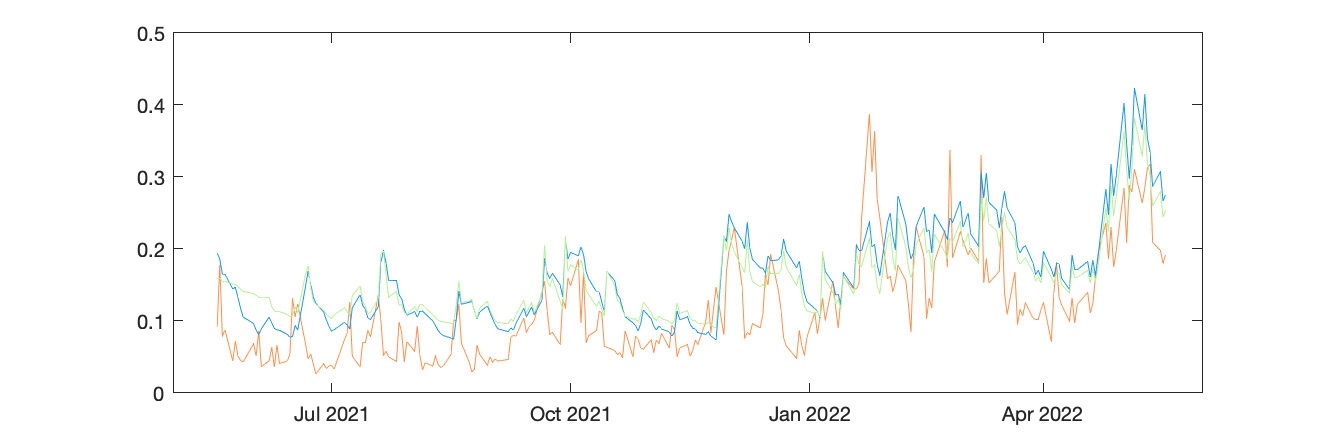

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
% legend("RV","GARCH","CPGARCH","CPGARCH Ite.");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_garchs.png'])

% Volatility forecasts: GJR, CPGJR, CPGJR iteration

Volatility forecasts: GJR, CPGJR, CPGJR iteration

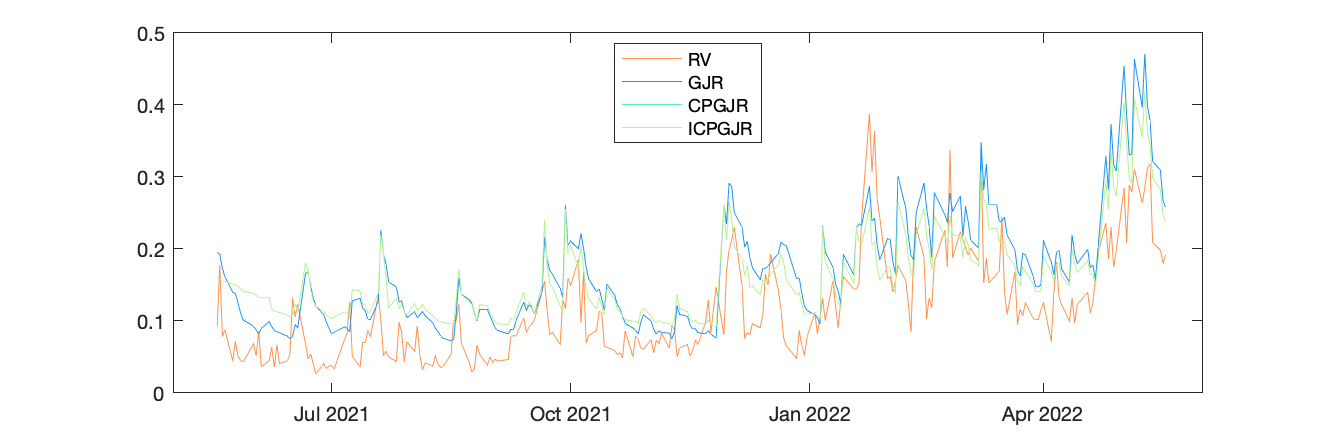

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(3,:))
legend("RV","GJR","CPGJR","ICPGJR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_gjrs.png'])

Volatility forecasts: RSGARCH, CPRSGARCH, CPRSGARCH iteration

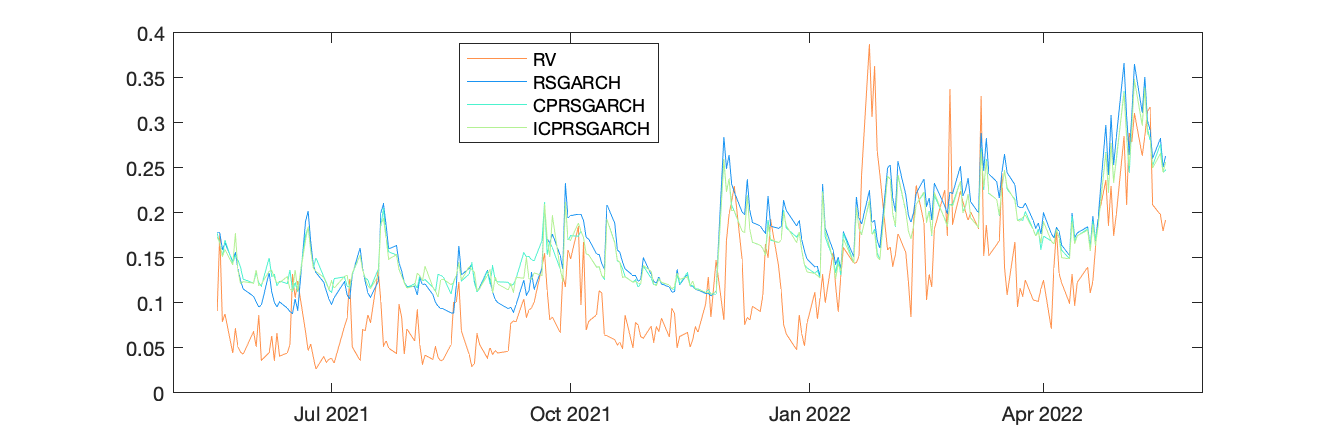

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_RSGARCH.vf_RSGARCH)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPRSGARCH.vf_CPRSGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)*sqrt(250), "Color",col(3,:))
legend("RV","RSGARCH","CPRSGARCH","ICPRSGARCH",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_rsgarchs.png'])

Volatility forecasts: HAR, CPHAR, ICPHAR

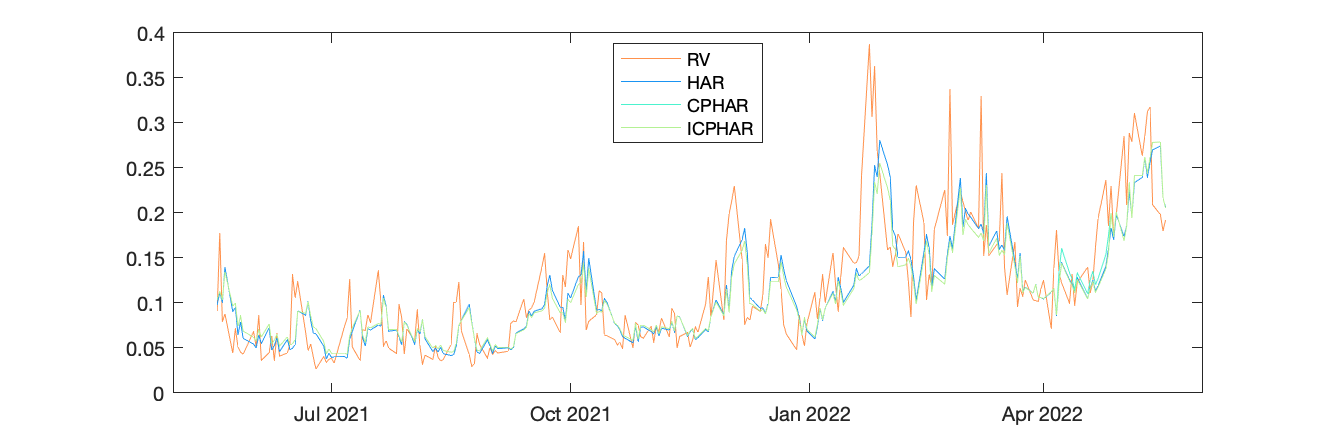

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(3,:))
legend("RV","HAR","CPHAR","ICPHAR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_hars.png'])

Volatility forecasts: HAR-a, CPHAR-a, ICPHAR-a

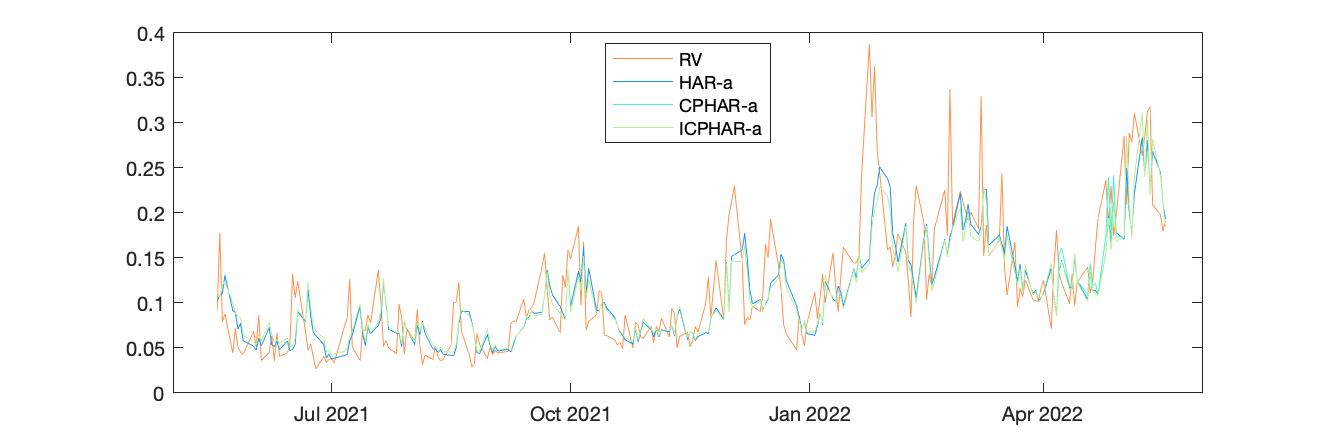

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(3,:))
legend("RV","HAR-a","CPHAR-a","ICPHAR-a",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_haras.png'])

#### Figure of parameters in each estimation window

GARCH

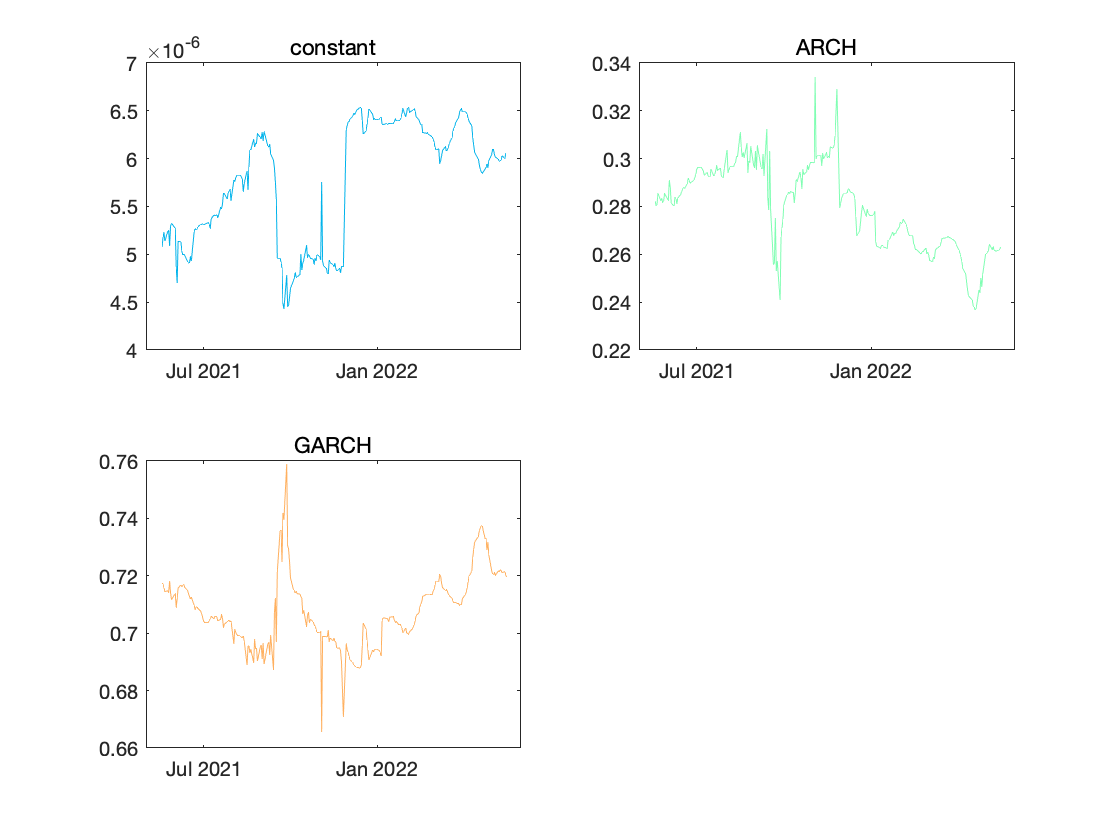

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,results_GARCH.para(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,results_GARCH.para(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,results_GARCH.para(:,3),"Color",col(3,:));
subtitle("GARCH")
saveas(gcf,[results_folder,'/dynamic_parameters_garch.png'])

#### Figure of optimal cluster number in each estimation window

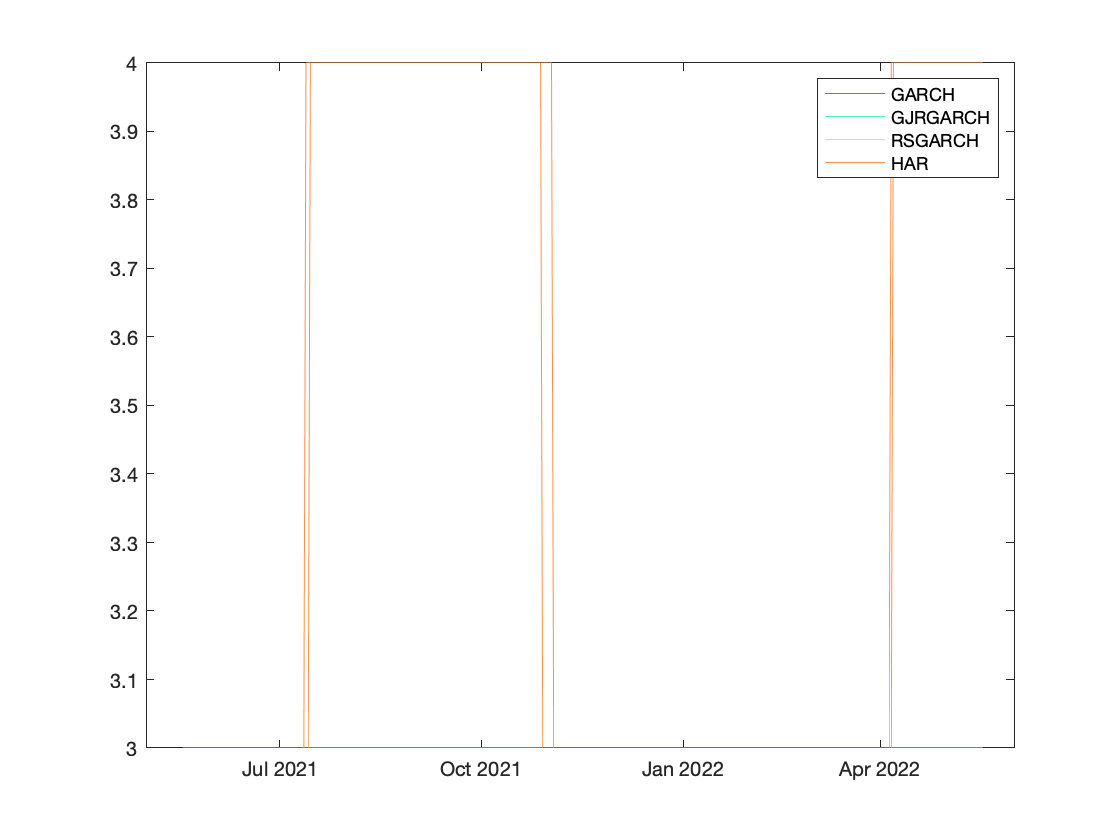

figure;
col=rainbow(4);
plot(Timeline_outsample,results_CPGARCH.K,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGJR.K,"Color",col(2,:));hold on
plot(Timeline_outsample,results_CPRSGARCH.K,"Color",col(3,:));
plot(Timeline_outsample,results_CPHAR.K,"Color",col(4,:));
plot(Timeline_outsample,results_CPHAR_a.K,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")
saveas(gcf,[results_folder,'/dynamic_optimal_cluster_number.png'])

Figure of in-sample MAE and MSE

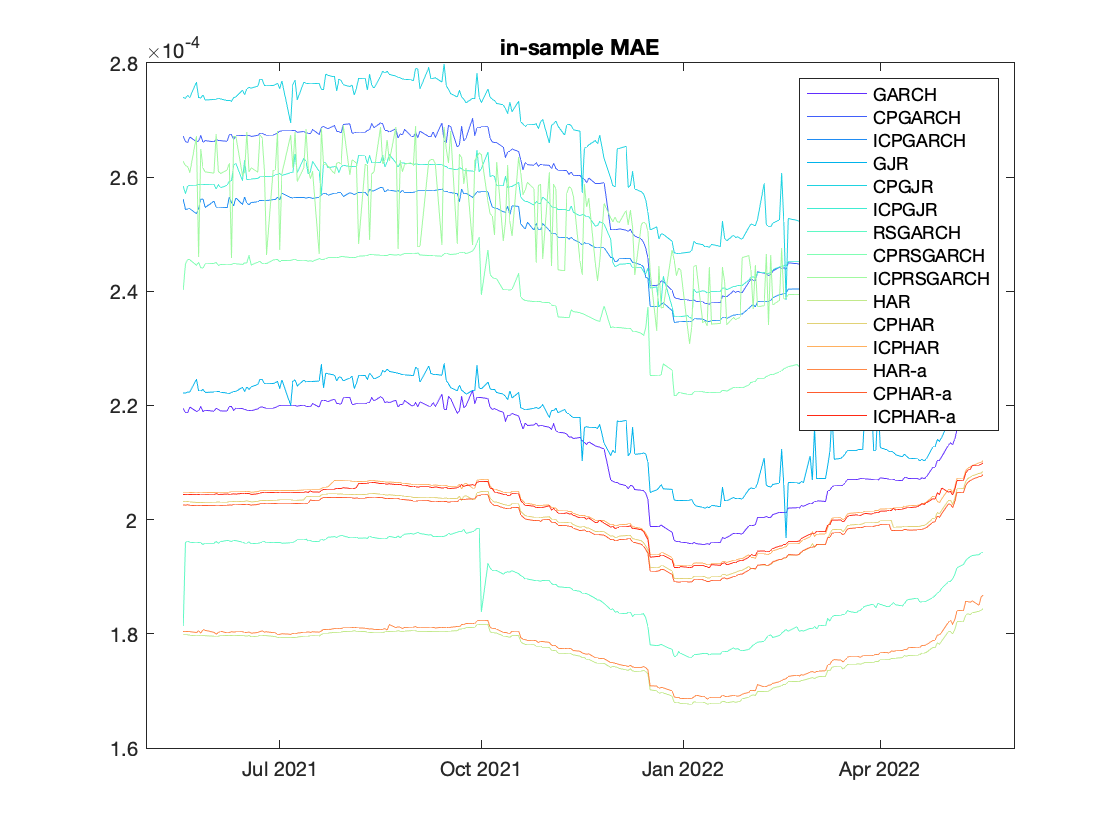

figure;
col=rainbow(15);
plot(Timeline_outsample,results_GARCH.ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.ismae_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.ismae_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_RSGARCH.ismae_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,results_CPRSGARCH.ismae_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,results_ICPRSGARCH.ismae_ICPRSGARCH,"Color",col(9,:));
plot(Timeline_outsample,results_HAR.ismae_HAR,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR.ismae_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR.ismae_ICPHAR,"Color",col(12,:));
plot(Timeline_outsample,results_HAR_a.ismae_HAR_a,"Color",col(13,:));
plot(Timeline_outsample,results_CPHAR_a.ismae_CPHAR_a,"Color",col(14,:));
plot(Timeline_outsample,results_ICPHAR_a.ismae_ICPHAR_a,"Color",col(15,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "RSGARCH","CPRSGARCH","ICPRSGARCH", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample MAE")
saveas(gcf,[results_folder,'/insample_mae.png'])

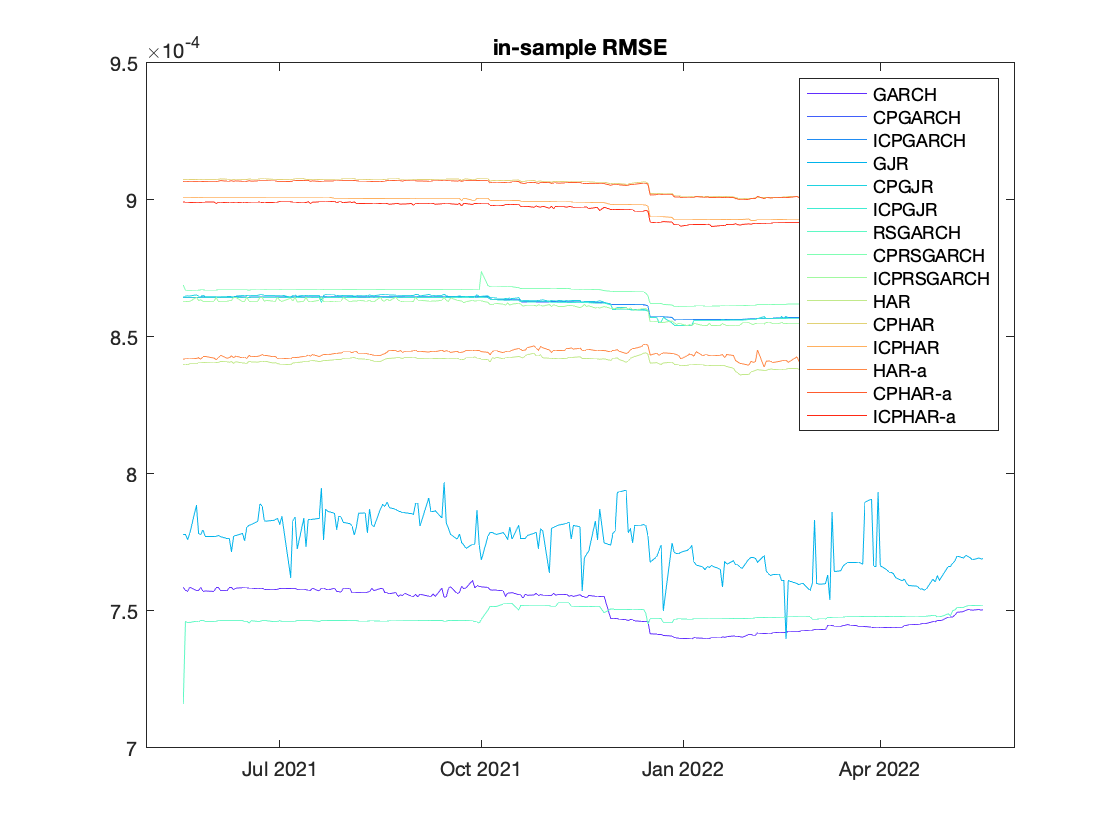

figure;
col=rainbow(15);
plot(Timeline_outsample,results_GARCH.isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.isrmse_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.isrmse_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_RSGARCH.isrmse_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,results_CPRSGARCH.isrmse_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,results_ICPRSGARCH.isrmse_ICPRSGARCH,"Color",col(9,:));
plot(Timeline_outsample,results_HAR.isrmse_HAR,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR.isrmse_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR.isrmse_ICPHAR,"Color",col(12,:));
plot(Timeline_outsample,results_HAR_a.isrmse_HAR_a,"Color",col(13,:));
plot(Timeline_outsample,results_CPHAR_a.isrmse_CPHAR_a,"Color",col(14,:));
plot(Timeline_outsample,results_ICPHAR_a.isrmse_ICPHAR_a,"Color",col(15,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "RSGARCH","CPRSGARCH","ICPRSGARCH", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample RMSE")
saveas(gcf,[results_folder,'/insample_rmse.png'])

MAE & RMSE

MAE=[mean(abs(sqrt(results_GARCH.vf_GARCH)-sqrt(rv)));mean(abs(sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_GJR.vf_GJR)-sqrt(rv)));mean(abs(sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)));mean(abs(sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)))
    mean(abs(sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)));mean(abs(sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_HAR.vf_HAR)-sqrt(rv)));mean(abs(sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)))
    mean(abs(sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)));mean(abs(sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)))]*sqrt(250);
RMSE=sqrt([mean((sqrt(results_GARCH.vf_GARCH)-sqrt(rv)).^2);mean((sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_GJR.vf_GJR)-sqrt(rv)).^2);mean((sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)).^2);mean((sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)).^2)
    mean((sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)).^2);mean((sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_HAR.vf_HAR)-sqrt(rv)).^2);mean((sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)).^2) 
    mean((sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)).^2);mean((sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)).^2)])*sqrt(250);
outsample_mae_rmse_allmodel=table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','ICPGARCH',...
    'GJRGARCH','CPGJRGARCH','ICPGJRGARCH.', ...
    'RSGARCH','CPRSGARCH','ICPRSGARCH','HAR','CPHAR','ICPHAR','HAR-a','CPHAR-a','ICPHAR-a'})

outsample_mae_rmse_allmodel = 15×2 table
                      MAE         RMSE  
                    ________    ________

    GARCH           0.057576    0.068542
    CPGARCH         0.053753    0.063345
    ICPGARCH        0.053753    0.063345
    GJRGARCH        0.059895    0.071739
    CPGJRGARCH      0.054535    0.063961
    ICPGJRGARCH.    0.054535    0.063961
    RSGARCH         0.063842    0.073829
    CPRSGARCH       0.061103    0.070202
    ICPRSGARCH      0.060404    0.069564
    HAR              0.03263    0.045541
    CPHAR           0.032461    0.045572
    ICPHAR          0.032528    0.045765
    HAR-a           0.032677    0.045534
    CPHAR-a         0.033284    0.046

ftxt=fopen([results_folder,'/outsample_mae_rmse_allmodel.txt'],'w+');
table2latex(outsample_mae_rmse_allmodel,ftxt)
fclose(ftxt);

DM test

fcst=readtable(['Volatility_Forecast_',Working_Date,'.xlsx']);
dm_test=nan(15,15);
for i=1:15
    for j=1:15
%         dm_test(i,j)=normcdf(dmtest(table2array(fcst(:,i+1))-rv,table2array(fcst(:,j+1))-rv),0,1);
%         dm_test(i,j)=dmtest(table2array(fcst(:,i+1))-rv,table2array(fcst(:,j+1))-rv);
        dm_test(i,j)=dmtest(table2array(fcst(:,i+1))-sqrt(rv),table2array(fcst(:,j+1))-sqrt(rv));
    end
end
dm_table=table(dm_test, ...
    'RowNames',{'GARCH','CPGARCH','ICPGARCH', ...
    'GJR','CPGJR','ICPGJR', ...
    'RSGARCH','CPRSGARCH','ICPRSGARCH', ...
    'HAR','CPHAR','ICPHAR', 'HAR-a','CPHAR-a','ICPHAR-a'})

dm_table = 15×1 table
                    dm_test  
                  ___________

    GARCH         1×15 double
    CPGARCH       1×15 double
    ICPGARCH      1×15 double
    GJR           1×15 double
    CPGJR         1×15 double
    ICPGJR        1×15 double
    RSGARCH       1×15 double
    CPRSGARCH     1×15 double
    ICPRSGARCH    1×15 double
    HAR           1×15 double
    CPHAR         1×15 double
    ICPHAR        1×15 double
    HAR-a         1×15 double
    CPHAR-a       1×15 double
    ICPHAR-a      1×15 double


ftxt=fopen([results_folder,'/dm_test.txt'],'w+');
table2latex(dm_table,ftxt)
fclose(ftxt);
toc

Elapsed time is 6424.059515 seconds.


## DAX

tic
Read_Name='DAX_0608.xlsx';
Time_Outsample=[2021,05,18;2022,05,18];
rv=get_rv(Read_Name,Time_Outsample);
Index_Name = 'DAX';
Working_Date = '20220913';
Window_Size = 750;
results_folder = get_results_folder(Index_Name,Working_Date);
Timeline_outsample = get_datetime_outofsample(Read_Name,Time_Outsample);
results_GARCH=VolFcst_GARCH(Read_Name,Time_Outsample);
results_CPGARCH=VolFcst_CPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGARCH: i=1
CPGARCH: i=2
CPGARCH: i=3
CPGARCH: i=4
CPGARCH: i=5
CPGARCH: i=6
CPGARCH: i=7
CPGARCH: i=8
CPGARCH: i=9
CPGARCH: i=10
CPGARCH: i=11
CPGARCH: i=12
CPGARCH: i=13
CPGARCH: i=14
CPGARCH: i=15
CPGARCH: i=16
CPGARCH: i=17
CPGARCH: i=18
CPGARCH: i=19
CPGARCH: i=20
CPGARCH: i=21
CPGARCH: i=22
CPGARCH: i=23
CPGARCH: i=24
CPGARCH: i=25
CPGARCH: i=26
CPGARCH: i=27
CPGARCH: i=28
CPGARCH: i=29
CPGARCH: i=30
CPGARCH: i=31
CPGARCH: i=32
CPGARCH: i=33
CPGARCH: i=34
CPGARCH: i=35
CPGARCH: i=36
CPGARCH: i=37
CPGARCH: i=38
CPGARCH: i=39
CPGARCH: i=40
CPGARCH: i=41
CPGARCH: i=42
CPGARCH: i=43
CPGARCH: i=44
CPGARCH: i=45
CPGARCH: i=46
CPGARCH: i=47
CPGARCH: i=48
CPGARCH: i=49
CPGARCH: i=50
CPGARCH: i=51
CPGARCH: i=52
CPGARCH: i=53
CPGARCH: i=54
CPGARCH: i=55
CPGARCH: i=56
CPGARCH: i=57
CPGARCH: i=58
CPGARCH: i=59
CPGARCH: i=60
CPGARCH: i=61
CPGARCH: i=62
CPGARCH: i=63
CPGARCH: i=64
CPGARCH: i=65
CPGARCH: i=66
CPGARCH: i=67
CPGARCH: i=68
CPGARCH: i=69
CPGARCH: i=70
CPGARCH: i=71
CPGARCH: i=72
C

results_ICPGARCH=VolFcst_ICPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGARCH: i=1
ICPGARCH: i=2
ICPGARCH: i=3
ICPGARCH: i=4
ICPGARCH: i=5
ICPGARCH: i=6
ICPGARCH: i=7
ICPGARCH: i=8
ICPGARCH: i=9
ICPGARCH: i=10
ICPGARCH: i=11
ICPGARCH: i=12
ICPGARCH: i=13
ICPGARCH: i=14
ICPGARCH: i=15
ICPGARCH: i=16
ICPGARCH: i=17
ICPGARCH: i=18
ICPGARCH: i=19
ICPGARCH: i=20
ICPGARCH: i=21
ICPGARCH: i=22
ICPGARCH: i=23
ICPGARCH: i=24
ICPGARCH: i=25
ICPGARCH: i=26
ICPGARCH: i=27
ICPGARCH: i=28
ICPGARCH: i=29
ICPGARCH: i=30
ICPGARCH: i=31
ICPGARCH: i=32
ICPGARCH: i=33
ICPGARCH: i=34
ICPGARCH: i=35
ICPGARCH: i=36
ICPGARCH: i=37
ICPGARCH: i=38
ICPGARCH: i=39
ICPGARCH: i=40
ICPGARCH: i=41
ICPGARCH: i=42
ICPGARCH: i=43
ICPGARCH: i=44
ICPGARCH: i=45
ICPGARCH: i=46
ICPGARCH: i=47
ICPGARCH: i=48
ICPGARCH: i=49
ICPGARCH: i=50
ICPGARCH: i=51
ICPGARCH: i=52
ICPGARCH: i=53
ICPGARCH: i=54
ICPGARCH: i=55
ICPGARCH: i=56
ICPGARCH: i=57
ICPGARCH: i=58
ICPGARCH: i=59
ICPGARCH: i=60
ICPGARCH: i=61
ICPGARCH: i=62
ICPGARCH: i=63
ICPGARCH: i=64
ICPGARCH: i=65
ICPGARCH: i=66
ICPGARCH: i=67
ICPG

results_GJR=VolFcst_GJR(Read_Name,Time_Outsample);
results_CPGJR=VolFcst_CPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGJR: i=216
CPGJR: i=217
CPGJR: i=218
CPGJR: i=219
CPGJR: i=220
CPGJR: i=221
CPGJR: i=222
CPGJR: i=223
CPGJR: i=224
CPGJR: i=225
CPGJR: i=226
CPGJR: i=227
CPGJR: i=228
CPGJR: i=229
CPGJR: i=230
CPGJR: i=231
CPGJR: i=232
CPGJR: i=233
CPGJR: i=234
CPGJR: i=235
CPGJR: i=236
CPGJR: i=237
CPGJR: i=238
CPGJR: i=239
CPGJR: i=240
CPGJR: i=241
CPGJR: i=242
CPGJR: i=243
CPGJR: i=244
CPGJR: i=245
CPGJR: i=246
CPGJR: i=247
CPGJR: i=248
CPGJR: i=249
CPGJR: i=250
CPGJR: i=251
CPGJR: i=252
CPGJR: i=253
CPGJR: i=254
CPGJR: i=255
CPGJR: i=256
CPGJR: i=257


results_ICPGJR=VolFcst_ICPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGJR: i=1
ICPGJR: i=2
ICPGJR: i=3
ICPGJR: i=4
ICPGJR: i=5
ICPGJR: i=6
ICPGJR: i=7
ICPGJR: i=8
ICPGJR: i=9
ICPGJR: i=10
ICPGJR: i=11
ICPGJR: i=12
ICPGJR: i=13
ICPGJR: i=14
ICPGJR: i=15
ICPGJR: i=16
ICPGJR: i=17
ICPGJR: i=18
ICPGJR: i=19
ICPGJR: i=20
ICPGJR: i=21
ICPGJR: i=22
ICPGJR: i=23
ICPGJR: i=24
ICPGJR: i=25
ICPGJR: i=26
ICPGJR: i=27
ICPGJR: i=28
ICPGJR: i=29
ICPGJR: i=30
ICPGJR: i=31
ICPGJR: i=32
ICPGJR: i=33
ICPGJR: i=34
ICPGJR: i=35
ICPGJR: i=36
ICPGJR: i=37
ICPGJR: i=38
ICPGJR: i=39
ICPGJR: i=40
ICPGJR: i=41
ICPGJR: i=42
ICPGJR: i=43
ICPGJR: i=44
ICPGJR: i=45
ICPGJR: i=46
ICPGJR: i=47
ICPGJR: i=48
ICPGJR: i=49
ICPGJR: i=50
ICPGJR: i=51
ICPGJR: i=52
ICPGJR: i=53
ICPGJR: i=54
ICPGJR: i=55
ICPGJR: i=56
ICPGJR: i=57
ICPGJR: i=58
ICPGJR: i=59
ICPGJR: i=60
ICPGJR: i=61
ICPGJR: i=62
ICPGJR: i=63
ICPGJR: i=64
ICPGJR: i=65
ICPGJR: i=66
ICPGJR: i=67
ICPGJR: i=68
ICPGJR: i=69
ICPGJR: i=70
ICPGJR: i=71
ICPGJR: i=72
ICPGJR: i=73
ICPGJR: i=74
ICPGJR: i=75
ICPGJR: i=76
ICPGJR: i=77
ICPGJR: 

results_RSGARCH=VolFcst_RSGARCH(Read_Name,Time_Outsample);

RSGARCH: i=1
RSGARCH: i=2
RSGARCH: i=3
RSGARCH: i=4
RSGARCH: i=5
RSGARCH: i=6
RSGARCH: i=7
RSGARCH: i=8
RSGARCH: i=9
RSGARCH: i=10
RSGARCH: i=11
RSGARCH: i=12
RSGARCH: i=13
RSGARCH: i=14
RSGARCH: i=15
RSGARCH: i=16
RSGARCH: i=17
RSGARCH: i=18
RSGARCH: i=19
RSGARCH: i=20
RSGARCH: i=21
RSGARCH: i=22
RSGARCH: i=23
RSGARCH: i=24
RSGARCH: i=25
RSGARCH: i=26
RSGARCH: i=27
RSGARCH: i=28
RSGARCH: i=29
RSGARCH: i=30
RSGARCH: i=31
RSGARCH: i=32
RSGARCH: i=33
RSGARCH: i=34
RSGARCH: i=35
RSGARCH: i=36
RSGARCH: i=37
RSGARCH: i=38
RSGARCH: i=39
RSGARCH: i=40
RSGARCH: i=41
RSGARCH: i=42
RSGARCH: i=43
RSGARCH: i=44
RSGARCH: i=45
RSGARCH: i=46
RSGARCH: i=47
RSGARCH: i=48
RSGARCH: i=49
RSGARCH: i=50
RSGARCH: i=51
RSGARCH: i=52
RSGARCH: i=53
RSGARCH: i=54
RSGARCH: i=55
RSGARCH: i=56
RSGARCH: i=57
RSGARCH: i=58
RSGARCH: i=59
RSGARCH: i=60
RSGARCH: i=61
RSGARCH: i=62
RSGARCH: i=63
RSGARCH: i=64
RSGARCH: i=65
RSGARCH: i=66
RSGARCH: i=67
RSGARCH: i=68
RSGARCH: i=69
RSGARCH: i=70
RSGARCH: i=71
RSGARCH: i=72
R

results_CPRSGARCH=VolFcst_CPRSGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPRSGARCH: i=1
CPRSGARCH: i=2
CPRSGARCH: i=3
CPRSGARCH: i=4
CPRSGARCH: i=5
CPRSGARCH: i=6
CPRSGARCH: i=7
CPRSGARCH: i=8
CPRSGARCH: i=9
CPRSGARCH: i=10
CPRSGARCH: i=11
CPRSGARCH: i=12
CPRSGARCH: i=13
CPRSGARCH: i=14
CPRSGARCH: i=15
CPRSGARCH: i=16
CPRSGARCH: i=17
CPRSGARCH: i=18
CPRSGARCH: i=19
CPRSGARCH: i=20
CPRSGARCH: i=21
CPRSGARCH: i=22
CPRSGARCH: i=23
CPRSGARCH: i=24
CPRSGARCH: i=25
CPRSGARCH: i=26
CPRSGARCH: i=27
CPRSGARCH: i=28
CPRSGARCH: i=29
CPRSGARCH: i=30
CPRSGARCH: i=31
CPRSGARCH: i=32
CPRSGARCH: i=33
CPRSGARCH: i=34
CPRSGARCH: i=35
CPRSGARCH: i=36
CPRSGARCH: i=37
CPRSGARCH: i=38
CPRSGARCH: i=39
CPRSGARCH: i=40
CPRSGARCH: i=41
CPRSGARCH: i=42
CPRSGARCH: i=43
CPRSGARCH: i=44
CPRSGARCH: i=45
CPRSGARCH: i=46
CPRSGARCH: i=47
CPRSGARCH: i=48
CPRSGARCH: i=49
CPRSGARCH: i=50
CPRSGARCH: i=51
CPRSGARCH: i=52
CPRSGARCH: i=53
CPRSGARCH: i=54
CPRSGARCH: i=55
CPRSGARCH: i=56
CPRSGARCH: i=57
CPRSGARCH: i=58
CPRSGARCH: i=59
CPRSGARCH: i=60
CPRSGARCH: i=61
CPRSGARCH: i=62
CPRSGARCH: i=63
C

results_ICPRSGARCH=VolFcst_ICPRSGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPRSGARCH: i=1


ICPRSGARCH: i=2


ICPRSGARCH: i=3


ICPRSGARCH: i=4


ICPRSGARCH: i=5


ICPRSGARCH: i=6


ICPRSGARCH: i=7


ICPRSGARCH: i=8


ICPRSGARCH: i=9


ICPRSGARCH: i=10


ICPRSGARCH: i=11


ICPRSGARCH: i=12


ICPRSGARCH: i=13


ICPRSGARCH: i=14


ICPRSGARCH: i=15


ICPRSGARCH: i=16


ICPRSGARCH: i=17


ICPRSGARCH: i=18


ICPRSGARCH: i=19


ICPRSGARCH: i=20


ICPRSGARCH: i=21


ICPRSGARCH: i=22


ICPRSGARCH: i=23


ICPRSGARCH: i=24


ICPRSGARCH: i=25


ICPRSGARCH: i=26


ICPRSGARCH: i=27


ICPRSGARCH: i=28


ICPRSGARCH: i=29


ICPRSGARCH: i=30


ICPRSGARCH: i=31


ICPRSGARCH: i=32


ICPRSGARCH: i=33


ICPRSGARCH: i=34


ICPRSGARCH: i=35


ICPRSGARCH: i=36


ICPRSGARCH: i=37


ICPRSGARCH: i=38


ICPRSGARCH: i=39


ICPRSGARCH: i=40


ICPRSGARCH: i=41


ICPRSGARCH: i=42


ICPRSGARCH: i=43


ICPRSGARCH: i=44


ICPRSGARCH: i=45


ICPRSGARCH: i=46


ICPRSGARCH: i=47


ICPRSGARCH: i=48


ICPRSGARCH: i=49


ICPRSGARCH: i=50


ICPRSGARCH: i=51


ICPRSGARCH: i=52


ICPRSGARCH: i=53


ICPRSGARCH: i=54


ICPRSGARCH: i=55


ICPRSGARCH: i=56


ICPRSGARCH: i=57


ICPRSGARCH: i=58


ICPRSGARCH: i=59


ICPRSGARCH: i=60


ICPRSGARCH: i=61


ICPRSGARCH: i=62


ICPRSGARCH: i=63


ICPRSGARCH: i=64


ICPRSGARCH: i=65


ICPRSGARCH: i=66


ICPRSGARCH: i=67


ICPRSGARCH: i=68


ICPRSGARCH: i=69


ICPRSGARCH: i=70


ICPRSGARCH: i=71


ICPRSGARCH: i=72


ICPRSGARCH: i=73


ICPRSGARCH: i=74


ICPRSGARCH: i=75


ICPRSGARCH: i=76


ICPRSGARCH: i=77


ICPRSGARCH: i=78


ICPRSGARCH: i=79


ICPRSGARCH: i=80


ICPRSGARCH: i=81


ICPRSGARCH: i=82


ICPRSGARCH: i=83


ICPRSGARCH: i=84


ICPRSGARCH: i=85


ICPRSGARCH: i=86


ICPRSGARCH: i=87


ICPRSGARCH: i=88


ICPRSGARCH: i=89


ICPRSGARCH: i=90


ICPRSGARCH: i=91


ICPRSGARCH: i=92


ICPRSGARCH: i=93


ICPRSGARCH: i=94


ICPRSGARCH: i=95


ICPRSGARCH: i=96


ICPRSGARCH: i=97


ICPRSGARCH: i=98


ICPRSGARCH: i=99


ICPRSGARCH: i=100


ICPRSGARCH: i=101


ICPRSGARCH: i=102


ICPRSGARCH: i=103


ICPRSGARCH: i=104


ICPRSGARCH: i=105


ICPRSGARCH: i=106


ICPRSGARCH: i=107


ICPRSGARCH: i=108


ICPRSGARCH: i=109


ICPRSGARCH: i=110


ICPRSGARCH: i=111


ICPRSGARCH: i=112


ICPRSGARCH: i=113


ICPRSGARCH: i=114


ICPRSGARCH: i=115


ICPRSGARCH: i=116


ICPRSGARCH: i=117


ICPRSGARCH: i=118


ICPRSGARCH: i=119


ICPRSGARCH: i=120


ICPRSGARCH: i=121


ICPRSGARCH: i=122


ICPRSGARCH: i=123


ICPRSGARCH: i=124


ICPRSGARCH: i=125


ICPRSGARCH: i=126


ICPRSGARCH: i=127


ICPRSGARCH: i=128


ICPRSGARCH: i=129


ICPRSGARCH: i=130


ICPRSGARCH: i=131


ICPRSGARCH: i=132


ICPRSGARCH: i=133


ICPRSGARCH: i=134


ICPRSGARCH: i=135


ICPRSGARCH: i=136


ICPRSGARCH: i=137


ICPRSGARCH: i=138


ICPRSGARCH: i=139


ICPRSGARCH: i=140


ICPRSGARCH: i=141


ICPRSGARCH: i=142


ICPRSGARCH: i=143


ICPRSGARCH: i=144


ICPRSGARCH: i=145


ICPRSGARCH: i=146


ICPRSGARCH: i=147


ICPRSGARCH: i=148


ICPRSGARCH: i=149


ICPRSGARCH: i=150


ICPRSGARCH: i=151


ICPRSGARCH: i=152


ICPRSGARCH: i=153


ICPRSGARCH: i=154


ICPRSGARCH: i=155


ICPRSGARCH: i=156


ICPRSGARCH: i=157


ICPRSGARCH: i=158


ICPRSGARCH: i=159


ICPRSGARCH: i=160


ICPRSGARCH: i=161


ICPRSGARCH: i=162


ICPRSGARCH: i=163


ICPRSGARCH: i=164


ICPRSGARCH: i=165


ICPRSGARCH: i=166


ICPRSGARCH: i=167


ICPRSGARCH: i=168


ICPRSGARCH: i=169


ICPRSGARCH: i=170


ICPRSGARCH: i=171


ICPRSGARCH: i=172


ICPRSGARCH: i=173


ICPRSGARCH: i=174


ICPRSGARCH: i=175


ICPRSGARCH: i=176


ICPRSGARCH: i=177


ICPRSGARCH: i=178


ICPRSGARCH: i=179


ICPRSGARCH: i=180


ICPRSGARCH: i=181


ICPRSGARCH: i=182


ICPRSGARCH: i=183


ICPRSGARCH: i=184


ICPRSGARCH: i=185


ICPRSGARCH: i=186


ICPRSGARCH: i=187


ICPRSGARCH: i=188


ICPRSGARCH: i=189


ICPRSGARCH: i=190


ICPRSGARCH: i=191


ICPRSGARCH: i=192


ICPRSGARCH: i=193


ICPRSGARCH: i=194


ICPRSGARCH: i=195


ICPRSGARCH: i=196


ICPRSGARCH: i=197


ICPRSGARCH: i=198


ICPRSGARCH: i=199


ICPRSGARCH: i=200


ICPRSGARCH: i=201


ICPRSGARCH: i=202


ICPRSGARCH: i=203


ICPRSGARCH: i=204


ICPRSGARCH: i=205


ICPRSGARCH: i=206


ICPRSGARCH: i=207


ICPRSGARCH: i=208


ICPRSGARCH: i=209


ICPRSGARCH: i=210


ICPRSGARCH: i=211


ICPRSGARCH: i=212


ICPRSGARCH: i=213


ICPRSGARCH: i=214


ICPRSGARCH: i=215


ICPRSGARCH: i=216


ICPRSGARCH: i=217


ICPRSGARCH: i=218


ICPRSGARCH: i=219


ICPRSGARCH: i=220


ICPRSGARCH: i=221


ICPRSGARCH: i=222


ICPRSGARCH: i=223


ICPRSGARCH: i=224


ICPRSGARCH: i=225


ICPRSGARCH: i=226


ICPRSGARCH: i=227


ICPRSGARCH: i=228


ICPRSGARCH: i=229


ICPRSGARCH: i=230


ICPRSGARCH: i=231


ICPRSGARCH: i=232


ICPRSGARCH: i=233


ICPRSGARCH: i=234


ICPRSGARCH: i=235


ICPRSGARCH: i=236


ICPRSGARCH: i=237


ICPRSGARCH: i=238


ICPRSGARCH: i=239


ICPRSGARCH: i=240


ICPRSGARCH: i=241


ICPRSGARCH: i=242


ICPRSGARCH: i=243


ICPRSGARCH: i=244


ICPRSGARCH: i=245


ICPRSGARCH: i=246


ICPRSGARCH: i=247


ICPRSGARCH: i=248


ICPRSGARCH: i=249


ICPRSGARCH: i=250


ICPRSGARCH: i=251


ICPRSGARCH: i=252


ICPRSGARCH: i=253


ICPRSGARCH: i=254


ICPRSGARCH: i=255


ICPRSGARCH: i=256


ICPRSGARCH: i=257


results_HAR=VolFcst_HAR(Read_Name,Time_Outsample);

HAR: i=1
HAR: i=2
HAR: i=3
HAR: i=4
HAR: i=5
HAR: i=6
HAR: i=7
HAR: i=8
HAR: i=9
HAR: i=10
HAR: i=11
HAR: i=12
HAR: i=13
HAR: i=14
HAR: i=15
HAR: i=16
HAR: i=17
HAR: i=18
HAR: i=19
HAR: i=20
HAR: i=21
HAR: i=22
HAR: i=23
HAR: i=24
HAR: i=25
HAR: i=26
HAR: i=27
HAR: i=28
HAR: i=29
HAR: i=30
HAR: i=31
HAR: i=32
HAR: i=33
HAR: i=34
HAR: i=35
HAR: i=36
HAR: i=37
HAR: i=38
HAR: i=39
HAR: i=40
HAR: i=41
HAR: i=42
HAR: i=43
HAR: i=44
HAR: i=45
HAR: i=46
HAR: i=47
HAR: i=48
HAR: i=49
HAR: i=50
HAR: i=51
HAR: i=52
HAR: i=53
HAR: i=54
HAR: i=55
HAR: i=56
HAR: i=57
HAR: i=58
HAR: i=59
HAR: i=60
HAR: i=61
HAR: i=62
HAR: i=63
HAR: i=64
HAR: i=65
HAR: i=66
HAR: i=67
HAR: i=68
HAR: i=69
HAR: i=70
HAR: i=71
HAR: i=72
HAR: i=73
HAR: i=74
HAR: i=75
HAR: i=76
HAR: i=77
HAR: i=78
HAR: i=79
HAR: i=80
HAR: i=81
HAR: i=82
HAR: i=83
HAR: i=84
HAR: i=85
HAR: i=86
HAR: i=87
HAR: i=88
HAR: i=89
HAR: i=90
HAR: i=91
HAR: i=92
HAR: i=93
HAR: i=94
HAR: i=95
HAR: i=96
HAR: i=97
HAR: i=98
HAR: i=99
HAR: i=100
HAR: i=1

results_CPHAR=VolFcst_CPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR: i=1
CPHAR: i=2
CPHAR: i=3
CPHAR: i=4
CPHAR: i=5
CPHAR: i=6
CPHAR: i=7
CPHAR: i=8
CPHAR: i=9
CPHAR: i=10
CPHAR: i=11
CPHAR: i=12
CPHAR: i=13
CPHAR: i=14
CPHAR: i=15
CPHAR: i=16
CPHAR: i=17
CPHAR: i=18
CPHAR: i=19
CPHAR: i=20
CPHAR: i=21
CPHAR: i=22
CPHAR: i=23
CPHAR: i=24
CPHAR: i=25
CPHAR: i=26
CPHAR: i=27
CPHAR: i=28
CPHAR: i=29
CPHAR: i=30
CPHAR: i=31
CPHAR: i=32
CPHAR: i=33
CPHAR: i=34
CPHAR: i=35
CPHAR: i=36
CPHAR: i=37
CPHAR: i=38
CPHAR: i=39
CPHAR: i=40
CPHAR: i=41
CPHAR: i=42
CPHAR: i=43
CPHAR: i=44
CPHAR: i=45
CPHAR: i=46
CPHAR: i=47
CPHAR: i=48
CPHAR: i=49
CPHAR: i=50
CPHAR: i=51
CPHAR: i=52
CPHAR: i=53
CPHAR: i=54
CPHAR: i=55
CPHAR: i=56
CPHAR: i=57
CPHAR: i=58
CPHAR: i=59
CPHAR: i=60
CPHAR: i=61
CPHAR: i=62
CPHAR: i=63
CPHAR: i=64
CPHAR: i=65
CPHAR: i=66
CPHAR: i=67
CPHAR: i=68
CPHAR: i=69
CPHAR: i=70
CPHAR: i=71
CPHAR: i=72
CPHAR: i=73
CPHAR: i=74
CPHAR: i=75
CPHAR: i=76
CPHAR: i=77
CPHAR: i=78
CPHAR: i=79
CPHAR: i=80
CPHAR: i=81
CPHAR: i=82
CPHAR: i=83
CPHAR: i=84
C

results_ICPHAR=VolFcst_ICPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR: i=1
ICPHAR: i=2
ICPHAR: i=3
ICPHAR: i=4
ICPHAR: i=5
ICPHAR: i=6
ICPHAR: i=7
ICPHAR: i=8
ICPHAR: i=9
ICPHAR: i=10
ICPHAR: i=11
ICPHAR: i=12
ICPHAR: i=13
ICPHAR: i=14
ICPHAR: i=15
ICPHAR: i=16
ICPHAR: i=17
ICPHAR: i=18
ICPHAR: i=19
ICPHAR: i=20
ICPHAR: i=21
ICPHAR: i=22
ICPHAR: i=23
ICPHAR: i=24
ICPHAR: i=25
ICPHAR: i=26
ICPHAR: i=27
ICPHAR: i=28
ICPHAR: i=29
ICPHAR: i=30
ICPHAR: i=31
ICPHAR: i=32
ICPHAR: i=33
ICPHAR: i=34
ICPHAR: i=35
ICPHAR: i=36
ICPHAR: i=37
ICPHAR: i=38
ICPHAR: i=39
ICPHAR: i=40
ICPHAR: i=41
ICPHAR: i=42
ICPHAR: i=43
ICPHAR: i=44
ICPHAR: i=45
ICPHAR: i=46
ICPHAR: i=47
ICPHAR: i=48
ICPHAR: i=49
ICPHAR: i=50
ICPHAR: i=51
ICPHAR: i=52
ICPHAR: i=53
ICPHAR: i=54
ICPHAR: i=55
ICPHAR: i=56
ICPHAR: i=57
ICPHAR: i=58
ICPHAR: i=59
ICPHAR: i=60
ICPHAR: i=61
ICPHAR: i=62
ICPHAR: i=63
ICPHAR: i=64
ICPHAR: i=65
ICPHAR: i=66
ICPHAR: i=67
ICPHAR: i=68
ICPHAR: i=69
ICPHAR: i=70
ICPHAR: i=71
ICPHAR: i=72
ICPHAR: i=73
ICPHAR: i=74
ICPHAR: i=75
ICPHAR: i=76
ICPHAR: i=77
ICPHAR: 

results_HAR_a=VolFcst_HAR_a(Read_Name,Time_Outsample);

HAR-a: i=1
HAR-a: i=2
HAR-a: i=3
HAR-a: i=4
HAR-a: i=5
HAR-a: i=6
HAR-a: i=7
HAR-a: i=8
HAR-a: i=9
HAR-a: i=10
HAR-a: i=11
HAR-a: i=12
HAR-a: i=13
HAR-a: i=14
HAR-a: i=15
HAR-a: i=16
HAR-a: i=17
HAR-a: i=18
HAR-a: i=19
HAR-a: i=20
HAR-a: i=21
HAR-a: i=22
HAR-a: i=23
HAR-a: i=24
HAR-a: i=25
HAR-a: i=26
HAR-a: i=27
HAR-a: i=28
HAR-a: i=29
HAR-a: i=30
HAR-a: i=31
HAR-a: i=32
HAR-a: i=33
HAR-a: i=34
HAR-a: i=35
HAR-a: i=36
HAR-a: i=37
HAR-a: i=38
HAR-a: i=39
HAR-a: i=40
HAR-a: i=41
HAR-a: i=42
HAR-a: i=43
HAR-a: i=44
HAR-a: i=45
HAR-a: i=46
HAR-a: i=47
HAR-a: i=48
HAR-a: i=49
HAR-a: i=50
HAR-a: i=51
HAR-a: i=52
HAR-a: i=53
HAR-a: i=54
HAR-a: i=55
HAR-a: i=56
HAR-a: i=57
HAR-a: i=58
HAR-a: i=59
HAR-a: i=60
HAR-a: i=61
HAR-a: i=62
HAR-a: i=63
HAR-a: i=64
HAR-a: i=65
HAR-a: i=66
HAR-a: i=67
HAR-a: i=68
HAR-a: i=69
HAR-a: i=70
HAR-a: i=71
HAR-a: i=72
HAR-a: i=73
HAR-a: i=74
HAR-a: i=75
HAR-a: i=76
HAR-a: i=77
HAR-a: i=78
HAR-a: i=79
HAR-a: i=80
HAR-a: i=81
HAR-a: i=82
HAR-a: i=83
HAR-a: i=84
H

results_CPHAR_a=VolFcst_CPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR-a: i=1
CPHAR-a: i=2
CPHAR-a: i=3
CPHAR-a: i=4
CPHAR-a: i=5
CPHAR-a: i=6
CPHAR-a: i=7
CPHAR-a: i=8
CPHAR-a: i=9
CPHAR-a: i=10
CPHAR-a: i=11
CPHAR-a: i=12
CPHAR-a: i=13
CPHAR-a: i=14
CPHAR-a: i=15
CPHAR-a: i=16
CPHAR-a: i=17
CPHAR-a: i=18
CPHAR-a: i=19
CPHAR-a: i=20
CPHAR-a: i=21
CPHAR-a: i=22
CPHAR-a: i=23
CPHAR-a: i=24
CPHAR-a: i=25
CPHAR-a: i=26
CPHAR-a: i=27
CPHAR-a: i=28
CPHAR-a: i=29
CPHAR-a: i=30
CPHAR-a: i=31
CPHAR-a: i=32
CPHAR-a: i=33
CPHAR-a: i=34
CPHAR-a: i=35
CPHAR-a: i=36
CPHAR-a: i=37
CPHAR-a: i=38
CPHAR-a: i=39
CPHAR-a: i=40
CPHAR-a: i=41
CPHAR-a: i=42
CPHAR-a: i=43
CPHAR-a: i=44
CPHAR-a: i=45
CPHAR-a: i=46
CPHAR-a: i=47
CPHAR-a: i=48
CPHAR-a: i=49
CPHAR-a: i=50
CPHAR-a: i=51
CPHAR-a: i=52
CPHAR-a: i=53
CPHAR-a: i=54
CPHAR-a: i=55
CPHAR-a: i=56
CPHAR-a: i=57
CPHAR-a: i=58
CPHAR-a: i=59
CPHAR-a: i=60
CPHAR-a: i=61
CPHAR-a: i=62
CPHAR-a: i=63
CPHAR-a: i=64
CPHAR-a: i=65
CPHAR-a: i=66
CPHAR-a: i=67
CPHAR-a: i=68
CPHAR-a: i=69
CPHAR-a: i=70
CPHAR-a: i=71
CPHAR-a: i=72
C

results_ICPHAR_a=VolFcst_ICPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR-a: i=1
ICPHAR-a: i=2
ICPHAR-a: i=3
ICPHAR-a: i=4
ICPHAR-a: i=5
ICPHAR-a: i=6
ICPHAR-a: i=7
ICPHAR-a: i=8
ICPHAR-a: i=9
ICPHAR-a: i=10
ICPHAR-a: i=11
ICPHAR-a: i=12
ICPHAR-a: i=13
ICPHAR-a: i=14
ICPHAR-a: i=15
ICPHAR-a: i=16
ICPHAR-a: i=17
ICPHAR-a: i=18
ICPHAR-a: i=19
ICPHAR-a: i=20
ICPHAR-a: i=21
ICPHAR-a: i=22
ICPHAR-a: i=23
ICPHAR-a: i=24
ICPHAR-a: i=25
ICPHAR-a: i=26
ICPHAR-a: i=27
ICPHAR-a: i=28
ICPHAR-a: i=29
ICPHAR-a: i=30
ICPHAR-a: i=31
ICPHAR-a: i=32
ICPHAR-a: i=33
ICPHAR-a: i=34
ICPHAR-a: i=35
ICPHAR-a: i=36
ICPHAR-a: i=37
ICPHAR-a: i=38
ICPHAR-a: i=39
ICPHAR-a: i=40
ICPHAR-a: i=41
ICPHAR-a: i=42
ICPHAR-a: i=43
ICPHAR-a: i=44
ICPHAR-a: i=45
ICPHAR-a: i=46
ICPHAR-a: i=47
ICPHAR-a: i=48
ICPHAR-a: i=49
ICPHAR-a: i=50
ICPHAR-a: i=51
ICPHAR-a: i=52
ICPHAR-a: i=53
ICPHAR-a: i=54
ICPHAR-a: i=55
ICPHAR-a: i=56
ICPHAR-a: i=57
ICPHAR-a: i=58
ICPHAR-a: i=59
ICPHAR-a: i=60
ICPHAR-a: i=61
ICPHAR-a: i=62
ICPHAR-a: i=63
ICPHAR-a: i=64
ICPHAR-a: i=65
ICPHAR-a: i=66
ICPHAR-a: i=67
ICPH

#### Save forecast volatility

Model_Name={'GARCH','CPGARCH','ICPGARCH',...
        'GJR','CPGJR','ICPGJR', ...
        'RSGARCH','CPRSGARCH','ICPRSGARCH',...
        'HAR','CPHAR','ICPHAR',...
        'HAR_a','CPHAR_a','ICPHAR_a'};
for i=1:15
    save([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date],['results_',Model_Name{i}]);
end
Output_Table=table(Timeline_outsample,sqrt(results_GARCH.vf_GARCH),sqrt(results_CPGARCH.vf_CPGARCH),sqrt(results_ICPGARCH.vf_ICPGARCH), ...
    sqrt(results_GJR.vf_GJR),sqrt(results_CPGJR.vf_CPGJR),sqrt(results_ICPGJR.vf_ICPGJR), ...
    sqrt(results_RSGARCH.vf_RSGARCH),sqrt(results_CPRSGARCH.vf_CPRSGARCH),sqrt(results_ICPRSGARCH.vf_ICPRSGARCH), ...
    sqrt(results_HAR.vf_HAR),sqrt(results_CPHAR.vf_CPHAR),sqrt(results_ICPHAR.vf_ICPHAR), ...
    sqrt(results_HAR_a.vf_HAR_a),sqrt(results_CPHAR_a.vf_CPHAR_a),sqrt(results_ICPHAR_a.vf_ICPHAR_a), ...
    'VariableNames',{'Date','vf_GARCH','vf_CPGARCH','vf_ICPGARCH', ...
    'vf_GJR','vf_CPGJR','vf_ICPGJR', ...
    'vf_RSGARCH','vf_CPRSGARCH','vf_ICPRSGARCH', ...
    'vf_HAR','vf_CPHAR','vf_ICPHAR', ...
    'vf_HAR_a','vf_CPHAR_a','vf_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Volatility_Forecast_',Working_Date,'.xlsx']);

#### Load forecast volatility

for i=1:15
    load([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date]);
end

Volatility forecasts: GARCH, CPGARCH, ICPGARCH,

GJR, CPGJR, ICPGJR, 

RSGARCH, CPRSGARCH, ICPRSGARCH, 

HAR, CPHAR, ICPHAR, HAR-a, CPHAR-a, ICPHAR-a

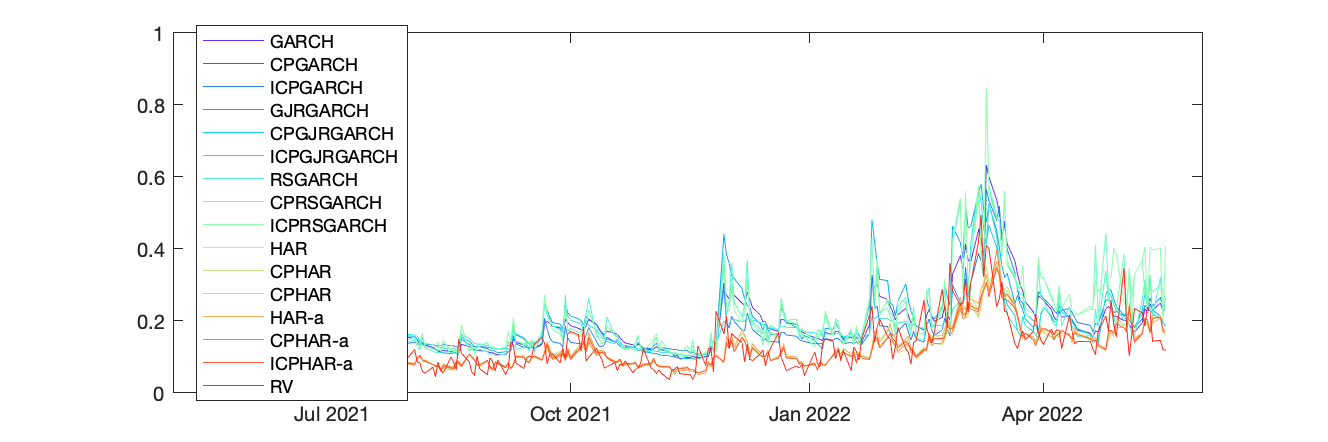

figure;
col=rainbow(16);
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(4,:));
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(5,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(6,:))
plot(Timeline_outsample,sqrt(results_RSGARCH.vf_RSGARCH)*sqrt(250), "Color",col(7,:));
plot(Timeline_outsample,sqrt(results_CPRSGARCH.vf_CPRSGARCH)*sqrt(250), "Color",col(8,:))
plot(Timeline_outsample,sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)*sqrt(250), "Color",col(9,:))
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(10,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(11,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(12,:))
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(13,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(14,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(15,:))
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(16,:))
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJRGARCH", "CPGJRGARCH", "ICPGJRGARCH", ...
    "RSGARCH", "CPRSGARCH", "ICPRSGARCH", ...
    "HAR","CPHAR","CPHAR", "HAR-a","CPHAR-a","ICPHAR-a", ...
    "RV","Location","best");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'_allmodel.png'])

Volatility forecasts: GARCH  CPGARCH, CPGARCH iteration

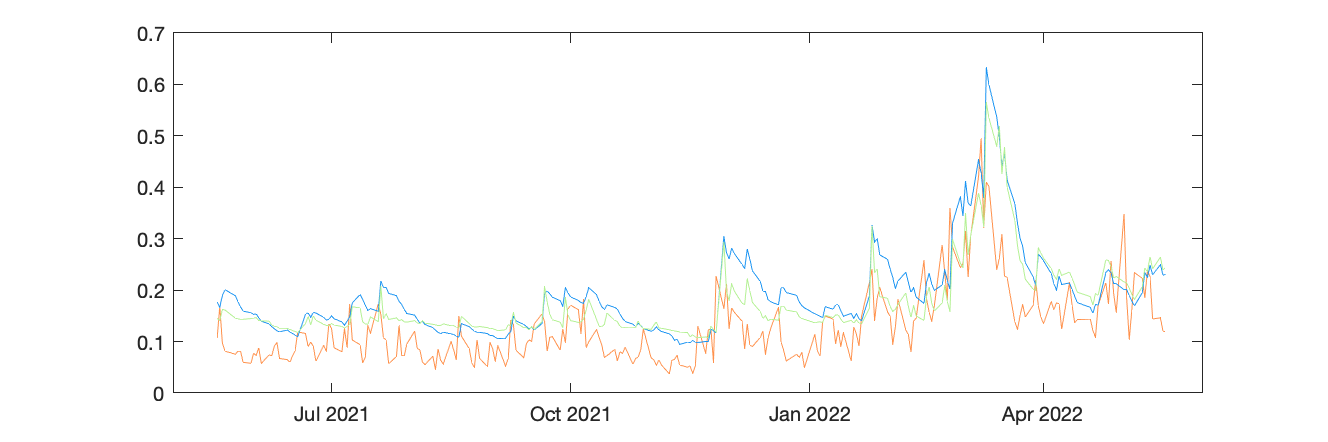

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
% legend("RV","GARCH","CPGARCH","CPGARCH Ite.");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'garchs.png'])

Volatility forecasts: GJR, CPGJR, CPGJR iteration

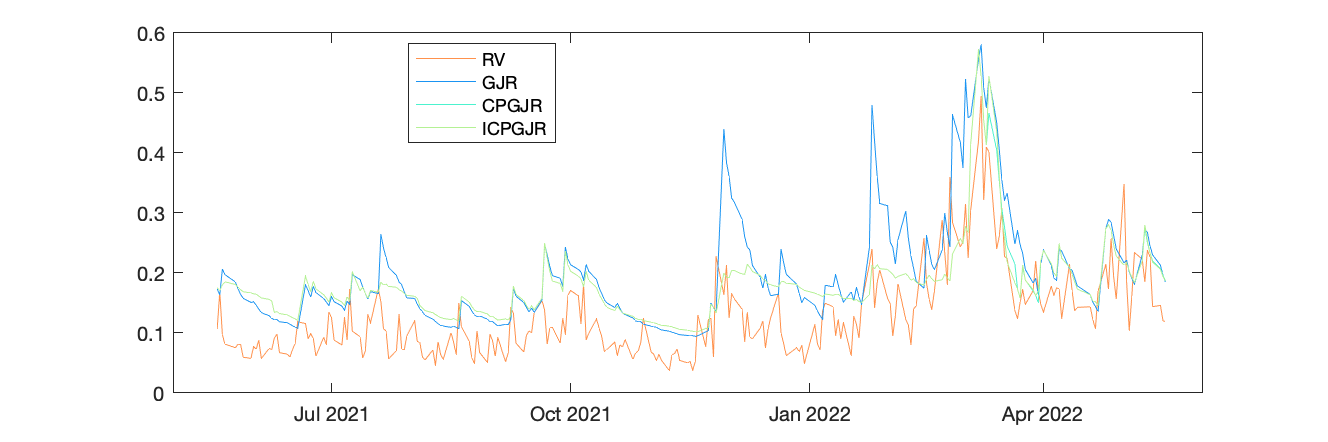

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(3,:))
legend("RV","GJR","CPGJR","ICPGJR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'gjrs.png'])

Volatility forecasts: RSGARCH, CPRSGARCH, CPRSGARCH iteration

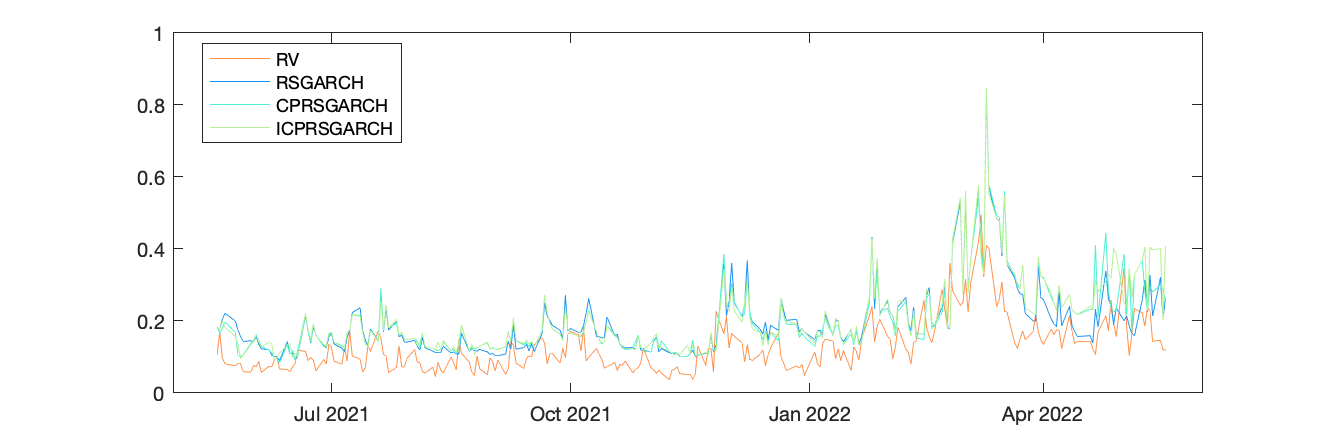

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_RSGARCH.vf_RSGARCH)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPRSGARCH.vf_CPRSGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)*sqrt(250), "Color",col(3,:))
legend("RV","RSGARCH","CPRSGARCH","ICPRSGARCH",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'rsgarchs.png'])

Volatility forecasts: HAR, CPHAR, ICPHAR

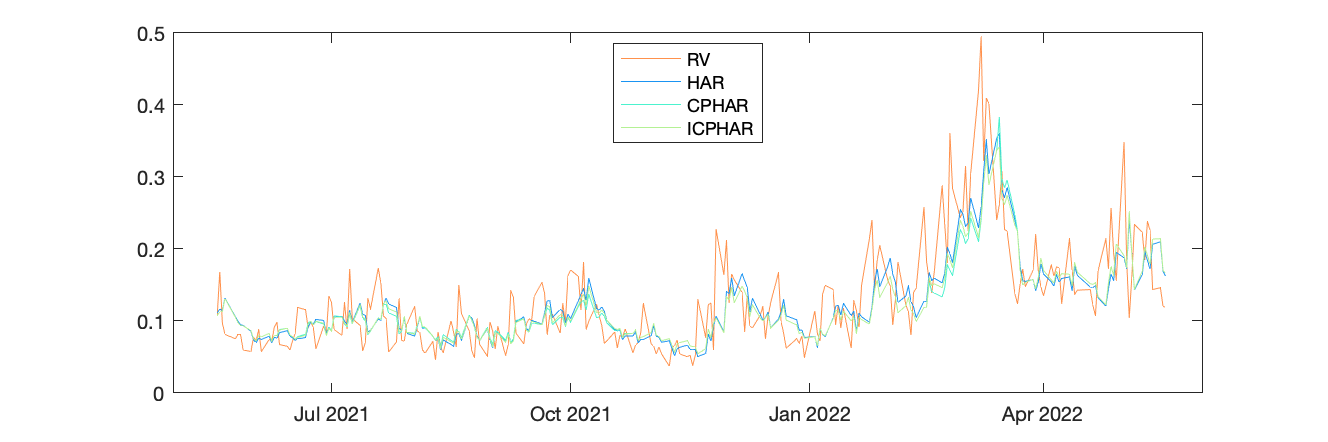

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(3,:))
legend("RV","HAR","CPHAR","ICPHAR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'hars.png'])

Volatility forecasts: HAR-a, CPHAR-a, ICPHAR-a

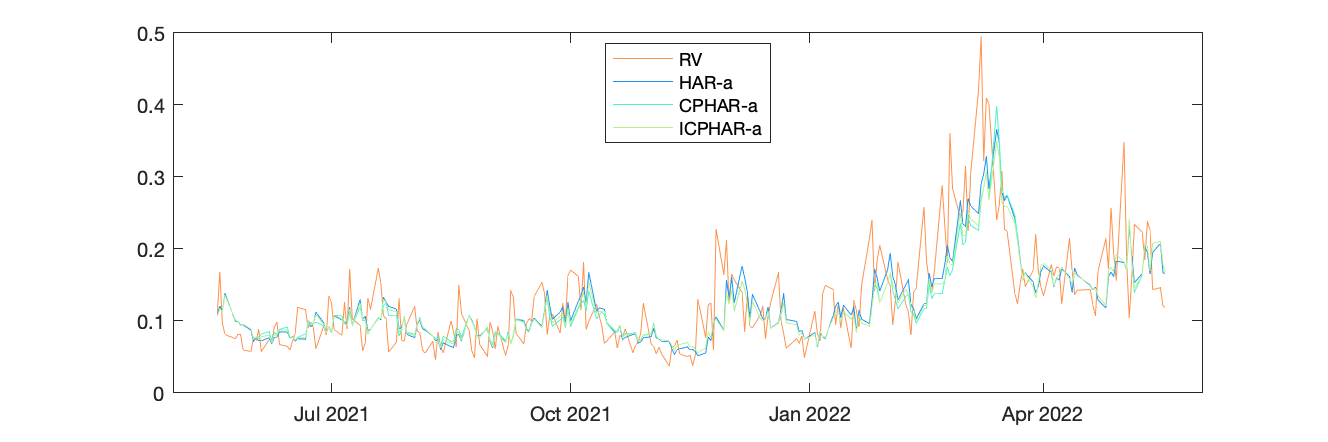

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(3,:))
legend("RV","HAR-a","CPHAR-a","ICPHAR-a",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'haras.png'])

#### Figure of parameters in each estimation window

GARCH

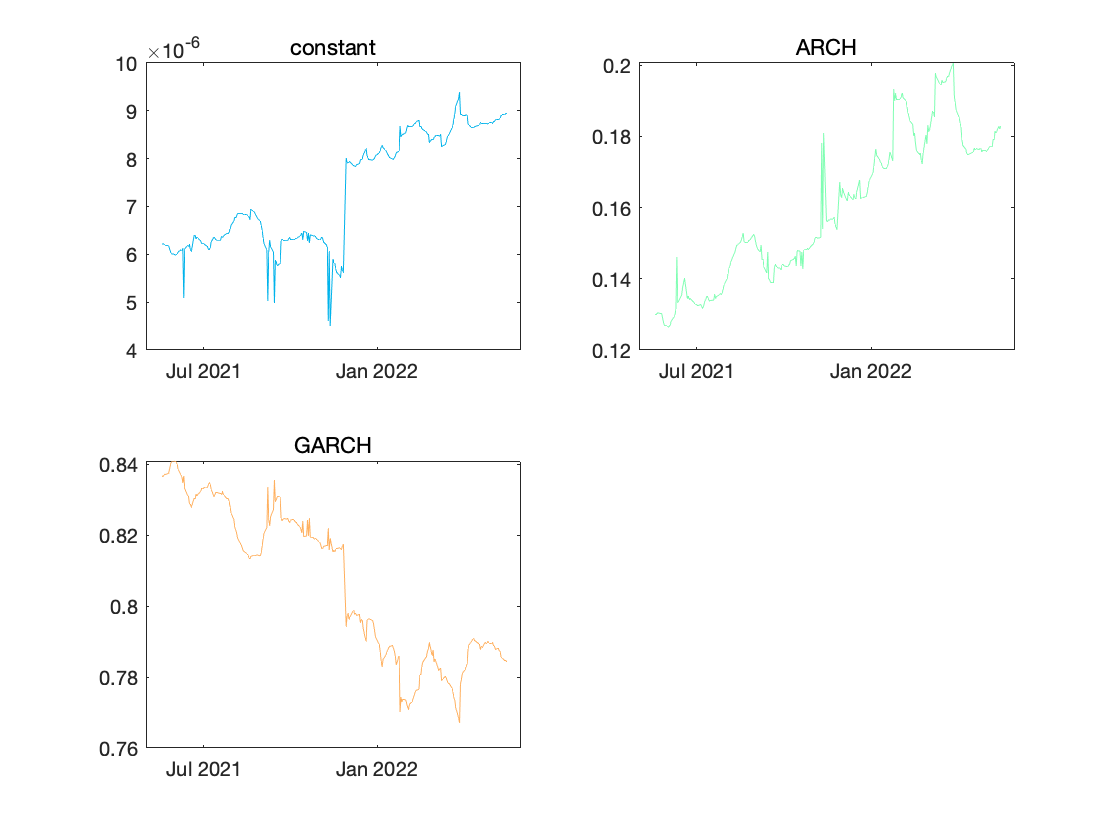

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,results_GARCH.para(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,results_GARCH.para(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,results_GARCH.para(:,3),"Color",col(3,:));
subtitle("GARCH")
saveas(gcf,[results_folder,'/dynamic_parameters_',Index_Name,'garch.png'])

#### Figure of optimal cluster number in each estimation window

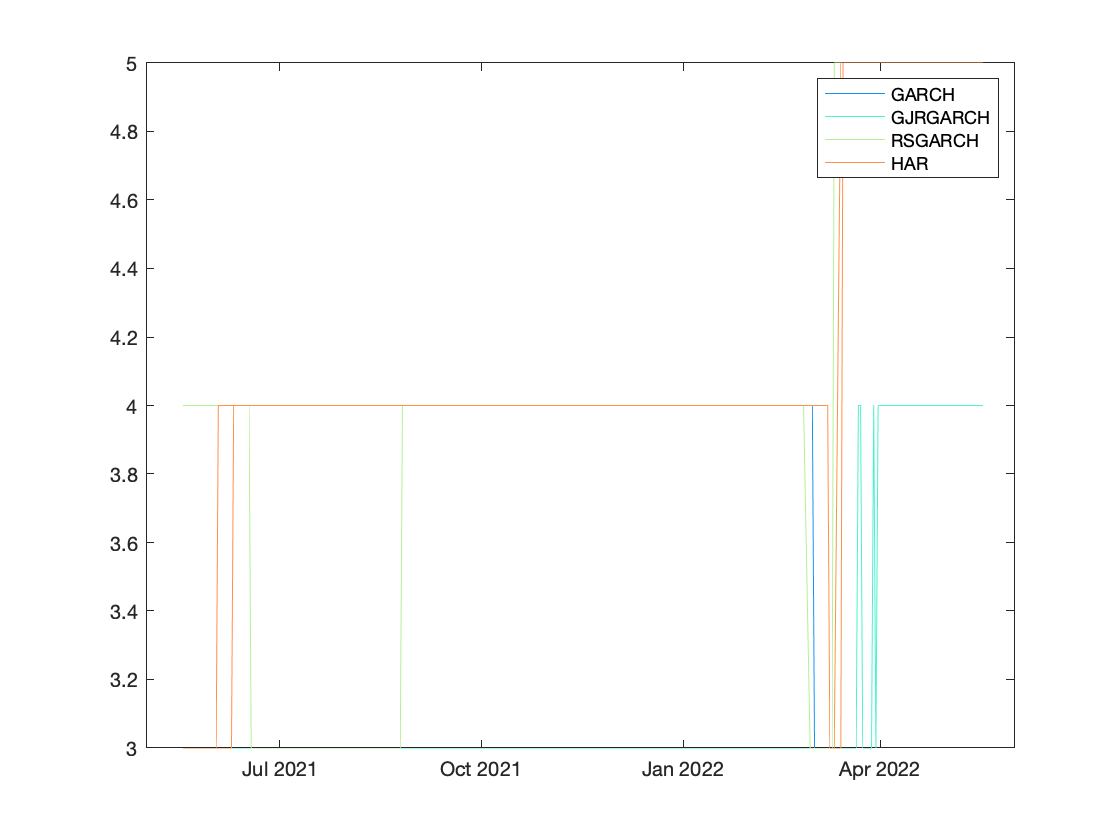

figure;
col=rainbow(4);
plot(Timeline_outsample,results_CPGARCH.K,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGJR.K,"Color",col(2,:));hold on
plot(Timeline_outsample,results_CPRSGARCH.K,"Color",col(3,:));
plot(Timeline_outsample,results_CPHAR.K,"Color",col(4,:));
plot(Timeline_outsample,results_CPHAR_a.K,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")
saveas(gcf,[results_folder,'/dynamic_optimal_cluster_number.png'])

#### Figure of in-sample MAE and MSE

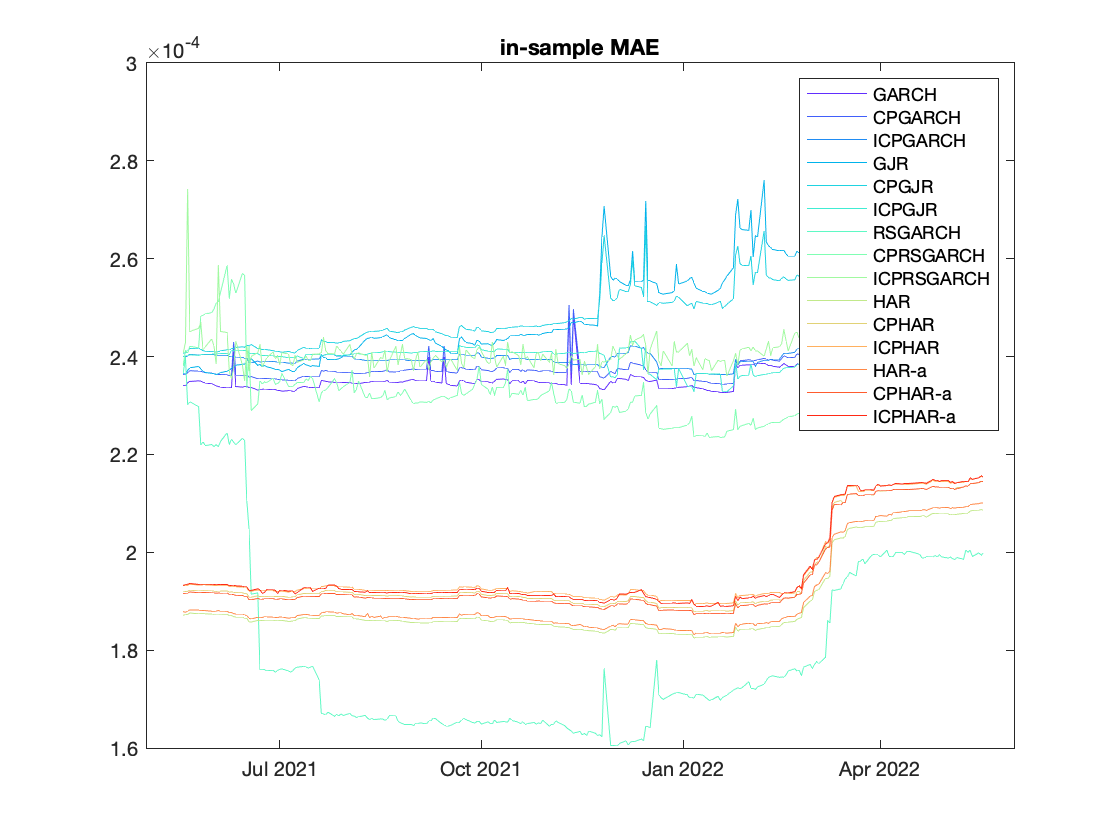

figure;
col=rainbow(15);
plot(Timeline_outsample,results_GARCH.ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.ismae_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.ismae_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_RSGARCH.ismae_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,results_CPRSGARCH.ismae_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,results_ICPRSGARCH.ismae_ICPRSGARCH,"Color",col(9,:));
plot(Timeline_outsample,results_HAR.ismae_HAR,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR.ismae_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR.ismae_ICPHAR,"Color",col(12,:));
plot(Timeline_outsample,results_HAR_a.ismae_HAR_a,"Color",col(13,:));
plot(Timeline_outsample,results_CPHAR_a.ismae_CPHAR_a,"Color",col(14,:));
plot(Timeline_outsample,results_ICPHAR_a.ismae_ICPHAR_a,"Color",col(15,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "RSGARCH","CPRSGARCH","ICPRSGARCH", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample MAE")
saveas(gcf,[results_folder,'/insample_mae.png'])

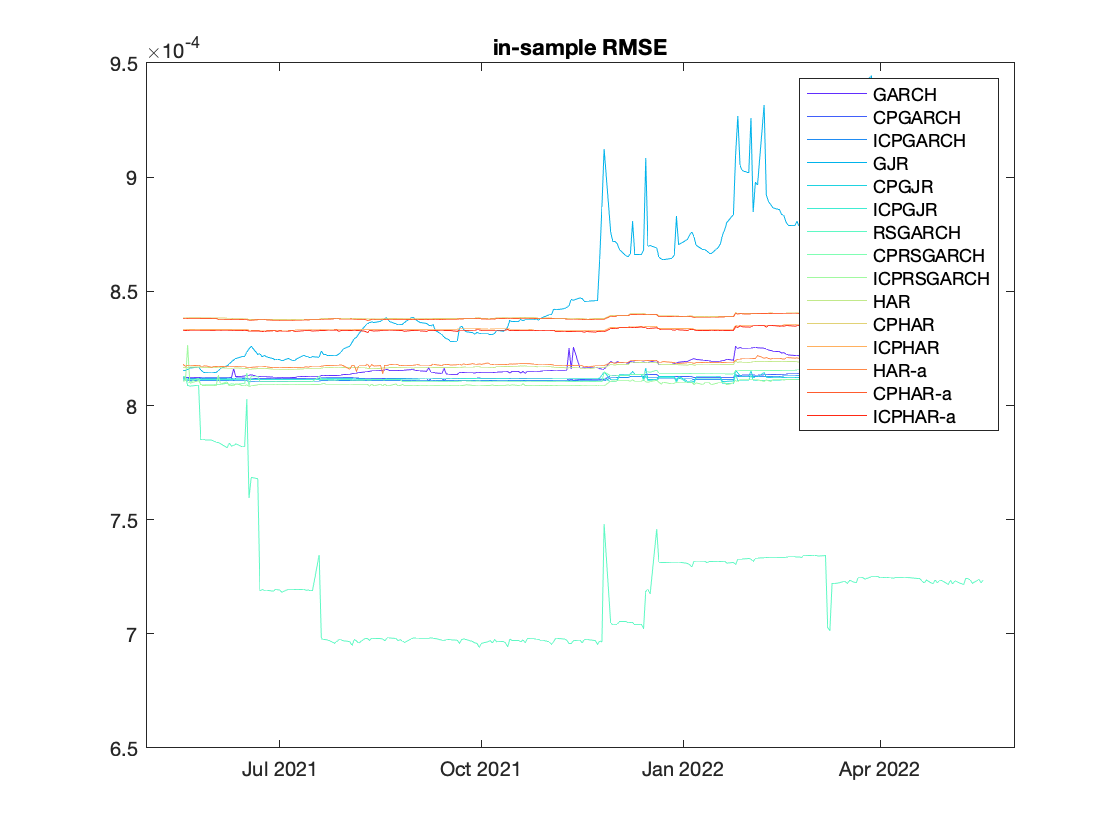

figure;
col=rainbow(15);
plot(Timeline_outsample,results_GARCH.isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.isrmse_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.isrmse_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_RSGARCH.isrmse_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,results_CPRSGARCH.isrmse_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,results_ICPRSGARCH.isrmse_ICPRSGARCH,"Color",col(9,:));
plot(Timeline_outsample,results_HAR.isrmse_HAR,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR.isrmse_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR.isrmse_ICPHAR,"Color",col(12,:));
plot(Timeline_outsample,results_HAR_a.isrmse_HAR_a,"Color",col(13,:));
plot(Timeline_outsample,results_CPHAR_a.isrmse_CPHAR_a,"Color",col(14,:));
plot(Timeline_outsample,results_ICPHAR_a.isrmse_ICPHAR_a,"Color",col(15,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "RSGARCH","CPRSGARCH","ICPRSGARCH", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample RMSE")
saveas(gcf,[results_folder,'/insample_rmse.png'])

#### MAE & RMSE

MAE=[mean(abs(sqrt(results_GARCH.vf_GARCH)-sqrt(rv)));mean(abs(sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_GJR.vf_GJR)-sqrt(rv)));mean(abs(sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)));mean(abs(sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)))
    mean(abs(sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)));mean(abs(sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_HAR.vf_HAR)-sqrt(rv)));mean(abs(sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)))
    mean(abs(sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)));mean(abs(sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)))]*sqrt(250);
RMSE=sqrt([mean((sqrt(results_GARCH.vf_GARCH)-sqrt(rv)).^2);mean((sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_GJR.vf_GJR)-sqrt(rv)).^2);mean((sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)).^2);mean((sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)).^2)
    mean((sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)).^2);mean((sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_HAR.vf_HAR)-sqrt(rv)).^2);mean((sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)).^2) 
    mean((sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)).^2);mean((sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)).^2)])*sqrt(250);
outsample_mae_rmse_allmodel=table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','ICPGARCH',...
    'GJRGARCH','CPGJRGARCH','ICPGJRGARCH.', ...
    'RSGARCH','CPRSGARCH','ICPRSGARCH','HAR','CPHAR','ICPHAR','HAR-a','CPHAR-a','ICPHAR-a'})

outsample_mae_rmse_allmodel = 15×2 table
                      MAE         RMSE  
                    ________    ________

    GARCH           0.070067    0.084362
    CPGARCH          0.05738    0.070345
    ICPGARCH         0.05738    0.070345
    GJRGARCH        0.075155     0.09015
    CPGJRGARCH      0.060388    0.069236
    ICPGJRGARCH.    0.060533    0.069766
    RSGARCH         0.074559    0.094629
    CPRSGARCH       0.078756    0.099569
    ICPRSGARCH      0.084119     0.10518
    HAR             0.035466    0.048779
    CPHAR           0.035674     0.05084
    ICPHAR          0.035154    0.049505
    HAR-a           0.035647    0.048187
    CPHAR-a         0.035938    0.050

ftxt=fopen([results_folder,'/outsample_mae_rmse_allmodel.txt'],'w+');
table2latex(outsample_mae_rmse_allmodel,ftxt)
fclose(ftxt);

#### DM test

fcst=readtable(['Volatility_Forecast_',Working_Date,'.xlsx']);
dm_test=nan(15,15);
for i=1:15
    for j=1:15
        dm_test(i,j)=dmtest(table2array(fcst(:,i+1))-sqrt(rv),table2array(fcst(:,j+1))-sqrt(rv));
    end
end
dm_table=table(dm_test, ...
    'RowNames',{'GARCH','CPGARCH','ICPGARCH', ...
    'GJR','CPGJR','ICPGJR', ...
    'RSGARCH','CPRSGARCH','ICPRSGARCH', ...
    'HAR','CPHAR','ICPHAR', 'HAR-a','CPHAR-a','ICPHAR-a'})

dm_table = 15×1 table
                    dm_test  
                  ___________

    GARCH         1×15 double
    CPGARCH       1×15 double
    ICPGARCH      1×15 double
    GJR           1×15 double
    CPGJR         1×15 double
    ICPGJR        1×15 double
    RSGARCH       1×15 double
    CPRSGARCH     1×15 double
    ICPRSGARCH    1×15 double
    HAR           1×15 double
    CPHAR         1×15 double
    ICPHAR        1×15 double
    HAR-a         1×15 double
    CPHAR-a       1×15 double
    ICPHAR-a      1×15 double


ftxt=fopen([results_folder,'/dm_test.txt'],'w+');
table2latex(dm_table,ftxt)
fclose(ftxt);
toc

Elapsed time is 13192.901742 seconds.


### FTSE

tic
Read_Name='FTSE_0608.xlsx';
Time_Outsample=[2021,05,18;2022,05,18];
rv=get_rv(Read_Name,Time_Outsample);
Index_Name = 'FTSE';
Working_Date = '20220913';
Window_Size = 750;
results_folder = get_results_folder(Index_Name,Working_Date);
Timeline_outsample = get_datetime_outofsample(Read_Name,Time_Outsample);
results_GARCH=VolFcst_GARCH(Read_Name,Time_Outsample);
results_CPGARCH=VolFcst_CPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGARCH: i=1
CPGARCH: i=2
CPGARCH: i=3
CPGARCH: i=4
CPGARCH: i=5
CPGARCH: i=6
CPGARCH: i=7
CPGARCH: i=8
CPGARCH: i=9
CPGARCH: i=10
CPGARCH: i=11
CPGARCH: i=12
CPGARCH: i=13
CPGARCH: i=14
CPGARCH: i=15
CPGARCH: i=16
CPGARCH: i=17
CPGARCH: i=18
CPGARCH: i=19
CPGARCH: i=20
CPGARCH: i=21
CPGARCH: i=22
CPGARCH: i=23
CPGARCH: i=24
CPGARCH: i=25
CPGARCH: i=26
CPGARCH: i=27
CPGARCH: i=28
CPGARCH: i=29
CPGARCH: i=30
CPGARCH: i=31
CPGARCH: i=32
CPGARCH: i=33
CPGARCH: i=34
CPGARCH: i=35
CPGARCH: i=36
CPGARCH: i=37
CPGARCH: i=38
CPGARCH: i=39
CPGARCH: i=40
CPGARCH: i=41
CPGARCH: i=42
CPGARCH: i=43
CPGARCH: i=44
CPGARCH: i=45
CPGARCH: i=46
CPGARCH: i=47
CPGARCH: i=48
CPGARCH: i=49
CPGARCH: i=50
CPGARCH: i=51
CPGARCH: i=52
CPGARCH: i=53
CPGARCH: i=54
CPGARCH: i=55
CPGARCH: i=56
CPGARCH: i=57
CPGARCH: i=58
CPGARCH: i=59
CPGARCH: i=60
CPGARCH: i=61
CPGARCH: i=62
CPGARCH: i=63
CPGARCH: i=64
CPGARCH: i=65
CPGARCH: i=66
CPGARCH: i=67
CPGARCH: i=68
CPGARCH: i=69
CPGARCH: i=70
CPGARCH: i=71
CPGARCH: i=72
C

results_ICPGARCH=VolFcst_ICPGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGARCH: i=1
ICPGARCH: i=2
ICPGARCH: i=3
ICPGARCH: i=4
ICPGARCH: i=5
ICPGARCH: i=6
ICPGARCH: i=7
ICPGARCH: i=8
ICPGARCH: i=9
ICPGARCH: i=10
ICPGARCH: i=11
ICPGARCH: i=12
ICPGARCH: i=13
ICPGARCH: i=14
ICPGARCH: i=15
ICPGARCH: i=16
ICPGARCH: i=17
ICPGARCH: i=18
ICPGARCH: i=19
ICPGARCH: i=20
ICPGARCH: i=21
ICPGARCH: i=22
ICPGARCH: i=23
ICPGARCH: i=24
ICPGARCH: i=25
ICPGARCH: i=26
ICPGARCH: i=27
ICPGARCH: i=28
ICPGARCH: i=29
ICPGARCH: i=30
ICPGARCH: i=31
ICPGARCH: i=32
ICPGARCH: i=33
ICPGARCH: i=34
ICPGARCH: i=35
ICPGARCH: i=36
ICPGARCH: i=37
ICPGARCH: i=38
ICPGARCH: i=39
ICPGARCH: i=40
ICPGARCH: i=41
ICPGARCH: i=42
ICPGARCH: i=43
ICPGARCH: i=44
ICPGARCH: i=45
ICPGARCH: i=46
ICPGARCH: i=47
ICPGARCH: i=48
ICPGARCH: i=49
ICPGARCH: i=50
ICPGARCH: i=51
ICPGARCH: i=52
ICPGARCH: i=53
ICPGARCH: i=54
ICPGARCH: i=55
ICPGARCH: i=56
ICPGARCH: i=57
ICPGARCH: i=58
ICPGARCH: i=59
ICPGARCH: i=60
ICPGARCH: i=61
ICPGARCH: i=62
ICPGARCH: i=63
ICPGARCH: i=64
ICPGARCH: i=65
ICPGARCH: i=66
ICPGARCH: i=67
ICPG

results_GJR=VolFcst_GJR(Read_Name,Time_Outsample);

GJR: i=1
GJR: i=2
GJR: i=3
GJR: i=4
GJR: i=5
GJR: i=6
GJR: i=7
GJR: i=8
GJR: i=9
GJR: i=10
GJR: i=11
GJR: i=12
GJR: i=13
GJR: i=14
GJR: i=15
GJR: i=16
GJR: i=17
GJR: i=18
GJR: i=19
GJR: i=20
GJR: i=21
GJR: i=22
GJR: i=23
GJR: i=24
GJR: i=25
GJR: i=26
GJR: i=27
GJR: i=28
GJR: i=29
GJR: i=30
GJR: i=31
GJR: i=32
GJR: i=33
GJR: i=34
GJR: i=35
GJR: i=36
GJR: i=37
GJR: i=38
GJR: i=39
GJR: i=40
GJR: i=41
GJR: i=42
GJR: i=43
GJR: i=44
GJR: i=45
GJR: i=46
GJR: i=47
GJR: i=48
GJR: i=49
GJR: i=50
GJR: i=51
GJR: i=52
GJR: i=53
GJR: i=54
GJR: i=55
GJR: i=56
GJR: i=57
GJR: i=58
GJR: i=59
GJR: i=60
GJR: i=61
GJR: i=62
GJR: i=63
GJR: i=64
GJR: i=65
GJR: i=66
GJR: i=67
GJR: i=68
GJR: i=69
GJR: i=70
GJR: i=71
GJR: i=72
GJR: i=73
GJR: i=74
GJR: i=75
GJR: i=76
GJR: i=77
GJR: i=78
GJR: i=79
GJR: i=80
GJR: i=81
GJR: i=82
GJR: i=83
GJR: i=84
GJR: i=85
GJR: i=86
GJR: i=87
GJR: i=88
GJR: i=89
GJR: i=90
GJR: i=91
GJR: i=92
GJR: i=93
GJR: i=94
GJR: i=95
GJR: i=96
GJR: i=97
GJR: i=98
GJR: i=99
GJR: i=100
GJR: i=1

results_CPGJR=VolFcst_CPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPGJR: i=1
CPGJR: i=2
CPGJR: i=3
CPGJR: i=4
CPGJR: i=5
CPGJR: i=6
CPGJR: i=7
CPGJR: i=8
CPGJR: i=9
CPGJR: i=10
CPGJR: i=11
CPGJR: i=12
CPGJR: i=13
CPGJR: i=14
CPGJR: i=15
CPGJR: i=16
CPGJR: i=17
CPGJR: i=18
CPGJR: i=19
CPGJR: i=20
CPGJR: i=21
CPGJR: i=22
CPGJR: i=23
CPGJR: i=24
CPGJR: i=25
CPGJR: i=26
CPGJR: i=27
CPGJR: i=28
CPGJR: i=29
CPGJR: i=30
CPGJR: i=31
CPGJR: i=32
CPGJR: i=33
CPGJR: i=34
CPGJR: i=35
CPGJR: i=36
CPGJR: i=37
CPGJR: i=38
CPGJR: i=39
CPGJR: i=40
CPGJR: i=41
CPGJR: i=42
CPGJR: i=43
CPGJR: i=44
CPGJR: i=45
CPGJR: i=46
CPGJR: i=47
CPGJR: i=48
CPGJR: i=49
CPGJR: i=50
CPGJR: i=51
CPGJR: i=52
CPGJR: i=53
CPGJR: i=54
CPGJR: i=55
CPGJR: i=56
CPGJR: i=57
CPGJR: i=58
CPGJR: i=59
CPGJR: i=60
CPGJR: i=61
CPGJR: i=62
CPGJR: i=63
CPGJR: i=64
CPGJR: i=65
CPGJR: i=66
CPGJR: i=67
CPGJR: i=68
CPGJR: i=69
CPGJR: i=70
CPGJR: i=71
CPGJR: i=72
CPGJR: i=73
CPGJR: i=74
CPGJR: i=75
CPGJR: i=76
CPGJR: i=77
CPGJR: i=78
CPGJR: i=79
CPGJR: i=80
CPGJR: i=81
CPGJR: i=82
CPGJR: i=83
CPGJR: i=84
C

results_ICPGJR=VolFcst_ICPGJR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPGJR: i=1
ICPGJR: i=2
ICPGJR: i=3
ICPGJR: i=4
ICPGJR: i=5
ICPGJR: i=6
ICPGJR: i=7
ICPGJR: i=8
ICPGJR: i=9
ICPGJR: i=10
ICPGJR: i=11
ICPGJR: i=12
ICPGJR: i=13
ICPGJR: i=14
ICPGJR: i=15
ICPGJR: i=16
ICPGJR: i=17
ICPGJR: i=18
ICPGJR: i=19
ICPGJR: i=20
ICPGJR: i=21
ICPGJR: i=22
ICPGJR: i=23
ICPGJR: i=24
ICPGJR: i=25
ICPGJR: i=26
ICPGJR: i=27
ICPGJR: i=28
ICPGJR: i=29
ICPGJR: i=30
ICPGJR: i=31
ICPGJR: i=32
ICPGJR: i=33
ICPGJR: i=34
ICPGJR: i=35
ICPGJR: i=36
ICPGJR: i=37
ICPGJR: i=38
ICPGJR: i=39
ICPGJR: i=40
ICPGJR: i=41
ICPGJR: i=42
ICPGJR: i=43
ICPGJR: i=44
ICPGJR: i=45
ICPGJR: i=46
ICPGJR: i=47
ICPGJR: i=48
ICPGJR: i=49
ICPGJR: i=50
ICPGJR: i=51
ICPGJR: i=52
ICPGJR: i=53
ICPGJR: i=54
ICPGJR: i=55
ICPGJR: i=56
ICPGJR: i=57
ICPGJR: i=58
ICPGJR: i=59
ICPGJR: i=60
ICPGJR: i=61
ICPGJR: i=62
ICPGJR: i=63
ICPGJR: i=64
ICPGJR: i=65
ICPGJR: i=66
ICPGJR: i=67
ICPGJR: i=68
ICPGJR: i=69
ICPGJR: i=70
ICPGJR: i=71
ICPGJR: i=72
ICPGJR: i=73
ICPGJR: i=74
ICPGJR: i=75
ICPGJR: i=76
ICPGJR: i=77
ICPGJR: 

results_RSGARCH=VolFcst_RSGARCH(Read_Name,Time_Outsample);

RSGARCH: i=1
RSGARCH: i=2
RSGARCH: i=3
RSGARCH: i=4
RSGARCH: i=5
RSGARCH: i=6
RSGARCH: i=7
RSGARCH: i=8
RSGARCH: i=9
RSGARCH: i=10
RSGARCH: i=11
RSGARCH: i=12
RSGARCH: i=13
RSGARCH: i=14
RSGARCH: i=15
RSGARCH: i=16
RSGARCH: i=17
RSGARCH: i=18
RSGARCH: i=19
RSGARCH: i=20
RSGARCH: i=21
RSGARCH: i=22
RSGARCH: i=23
RSGARCH: i=24
RSGARCH: i=25
RSGARCH: i=26
RSGARCH: i=27
RSGARCH: i=28
RSGARCH: i=29
RSGARCH: i=30
RSGARCH: i=31
RSGARCH: i=32
RSGARCH: i=33
RSGARCH: i=34
RSGARCH: i=35
RSGARCH: i=36
RSGARCH: i=37
RSGARCH: i=38
RSGARCH: i=39
RSGARCH: i=40
RSGARCH: i=41
RSGARCH: i=42
RSGARCH: i=43
RSGARCH: i=44
RSGARCH: i=45
RSGARCH: i=46
RSGARCH: i=47
RSGARCH: i=48
RSGARCH: i=49
RSGARCH: i=50
RSGARCH: i=51
RSGARCH: i=52
RSGARCH: i=53
RSGARCH: i=54
RSGARCH: i=55
RSGARCH: i=56
RSGARCH: i=57
RSGARCH: i=58
RSGARCH: i=59
RSGARCH: i=60
RSGARCH: i=61
RSGARCH: i=62
RSGARCH: i=63
RSGARCH: i=64
RSGARCH: i=65
RSGARCH: i=66
RSGARCH: i=67
RSGARCH: i=68
RSGARCH: i=69
RSGARCH: i=70
RSGARCH: i=71
RSGARCH: i=72
R

results_CPRSGARCH=VolFcst_CPRSGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPRSGARCH: i=1
CPRSGARCH: i=2
CPRSGARCH: i=3
CPRSGARCH: i=4
CPRSGARCH: i=5
CPRSGARCH: i=6
CPRSGARCH: i=7
CPRSGARCH: i=8
CPRSGARCH: i=9
CPRSGARCH: i=10
CPRSGARCH: i=11
CPRSGARCH: i=12
CPRSGARCH: i=13
CPRSGARCH: i=14
CPRSGARCH: i=15
CPRSGARCH: i=16
CPRSGARCH: i=17
CPRSGARCH: i=18
CPRSGARCH: i=19
CPRSGARCH: i=20
CPRSGARCH: i=21
CPRSGARCH: i=22
CPRSGARCH: i=23
CPRSGARCH: i=24
CPRSGARCH: i=25
CPRSGARCH: i=26
CPRSGARCH: i=27
CPRSGARCH: i=28
CPRSGARCH: i=29
CPRSGARCH: i=30
CPRSGARCH: i=31
CPRSGARCH: i=32
CPRSGARCH: i=33
CPRSGARCH: i=34
CPRSGARCH: i=35
CPRSGARCH: i=36
CPRSGARCH: i=37
CPRSGARCH: i=38
CPRSGARCH: i=39
CPRSGARCH: i=40
CPRSGARCH: i=41
CPRSGARCH: i=42
CPRSGARCH: i=43
CPRSGARCH: i=44
CPRSGARCH: i=45
CPRSGARCH: i=46
CPRSGARCH: i=47
CPRSGARCH: i=48
CPRSGARCH: i=49
CPRSGARCH: i=50
CPRSGARCH: i=51
CPRSGARCH: i=52
CPRSGARCH: i=53
CPRSGARCH: i=54
CPRSGARCH: i=55
CPRSGARCH: i=56
CPRSGARCH: i=57
CPRSGARCH: i=58
CPRSGARCH: i=59
CPRSGARCH: i=60
CPRSGARCH: i=61
CPRSGARCH: i=62
CPRSGARCH: i=63
C

results_ICPRSGARCH=VolFcst_ICPRSGARCH(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPRSGARCH: i=1


ICPRSGARCH: i=2


ICPRSGARCH: i=3


ICPRSGARCH: i=4


ICPRSGARCH: i=5


ICPRSGARCH: i=6


ICPRSGARCH: i=7


ICPRSGARCH: i=8


ICPRSGARCH: i=9


ICPRSGARCH: i=10


ICPRSGARCH: i=11


ICPRSGARCH: i=12


ICPRSGARCH: i=13


ICPRSGARCH: i=14


ICPRSGARCH: i=15


ICPRSGARCH: i=16


ICPRSGARCH: i=17


ICPRSGARCH: i=18


ICPRSGARCH: i=19


ICPRSGARCH: i=20


ICPRSGARCH: i=21


ICPRSGARCH: i=22


ICPRSGARCH: i=23


ICPRSGARCH: i=24


ICPRSGARCH: i=25


ICPRSGARCH: i=26


ICPRSGARCH: i=27


ICPRSGARCH: i=28


ICPRSGARCH: i=29


ICPRSGARCH: i=30


ICPRSGARCH: i=31


ICPRSGARCH: i=32


ICPRSGARCH: i=33


ICPRSGARCH: i=34


ICPRSGARCH: i=35


ICPRSGARCH: i=36


ICPRSGARCH: i=37


ICPRSGARCH: i=38


ICPRSGARCH: i=39


ICPRSGARCH: i=40


ICPRSGARCH: i=41


ICPRSGARCH: i=42


ICPRSGARCH: i=43


ICPRSGARCH: i=44


ICPRSGARCH: i=45


ICPRSGARCH: i=46


ICPRSGARCH: i=47


ICPRSGARCH: i=48


ICPRSGARCH: i=49


ICPRSGARCH: i=50


ICPRSGARCH: i=51


ICPRSGARCH: i=52


ICPRSGARCH: i=53


ICPRSGARCH: i=54


ICPRSGARCH: i=55


ICPRSGARCH: i=56


ICPRSGARCH: i=57


ICPRSGARCH: i=58


ICPRSGARCH: i=59


ICPRSGARCH: i=60


ICPRSGARCH: i=61


ICPRSGARCH: i=62


ICPRSGARCH: i=63


ICPRSGARCH: i=64


ICPRSGARCH: i=65


ICPRSGARCH: i=66


ICPRSGARCH: i=67


ICPRSGARCH: i=68


ICPRSGARCH: i=69


ICPRSGARCH: i=70


ICPRSGARCH: i=71


ICPRSGARCH: i=72


ICPRSGARCH: i=73


ICPRSGARCH: i=74


ICPRSGARCH: i=75


ICPRSGARCH: i=76


ICPRSGARCH: i=77


ICPRSGARCH: i=78


ICPRSGARCH: i=79


ICPRSGARCH: i=80


ICPRSGARCH: i=81


ICPRSGARCH: i=82


ICPRSGARCH: i=83


ICPRSGARCH: i=84


ICPRSGARCH: i=85


ICPRSGARCH: i=86


ICPRSGARCH: i=87


ICPRSGARCH: i=88


ICPRSGARCH: i=89


ICPRSGARCH: i=90


ICPRSGARCH: i=91


ICPRSGARCH: i=92


ICPRSGARCH: i=93


ICPRSGARCH: i=94


ICPRSGARCH: i=95


ICPRSGARCH: i=96


ICPRSGARCH: i=97


ICPRSGARCH: i=98


ICPRSGARCH: i=99


ICPRSGARCH: i=100


ICPRSGARCH: i=101


ICPRSGARCH: i=102


ICPRSGARCH: i=103


ICPRSGARCH: i=104


ICPRSGARCH: i=105


ICPRSGARCH: i=106


ICPRSGARCH: i=107


ICPRSGARCH: i=108


ICPRSGARCH: i=109


ICPRSGARCH: i=110


ICPRSGARCH: i=111


ICPRSGARCH: i=112


ICPRSGARCH: i=113


ICPRSGARCH: i=114


ICPRSGARCH: i=115


ICPRSGARCH: i=116


ICPRSGARCH: i=117


ICPRSGARCH: i=118


ICPRSGARCH: i=119


ICPRSGARCH: i=120


ICPRSGARCH: i=121


ICPRSGARCH: i=122


ICPRSGARCH: i=123


ICPRSGARCH: i=124


ICPRSGARCH: i=125


ICPRSGARCH: i=126


ICPRSGARCH: i=127


ICPRSGARCH: i=128


ICPRSGARCH: i=129


ICPRSGARCH: i=130


ICPRSGARCH: i=131


ICPRSGARCH: i=132


ICPRSGARCH: i=133


ICPRSGARCH: i=134


ICPRSGARCH: i=135


ICPRSGARCH: i=136


ICPRSGARCH: i=137


ICPRSGARCH: i=138


ICPRSGARCH: i=139


ICPRSGARCH: i=140


ICPRSGARCH: i=141


ICPRSGARCH: i=142


ICPRSGARCH: i=143


ICPRSGARCH: i=144


ICPRSGARCH: i=145


ICPRSGARCH: i=146


ICPRSGARCH: i=147


ICPRSGARCH: i=148


ICPRSGARCH: i=149


ICPRSGARCH: i=150


ICPRSGARCH: i=151


ICPRSGARCH: i=152


ICPRSGARCH: i=153


ICPRSGARCH: i=154


ICPRSGARCH: i=155


ICPRSGARCH: i=156


ICPRSGARCH: i=157


ICPRSGARCH: i=158


ICPRSGARCH: i=159


ICPRSGARCH: i=160


ICPRSGARCH: i=161


ICPRSGARCH: i=162


ICPRSGARCH: i=163


ICPRSGARCH: i=164


ICPRSGARCH: i=165


ICPRSGARCH: i=166


ICPRSGARCH: i=167


ICPRSGARCH: i=168


ICPRSGARCH: i=169


ICPRSGARCH: i=170


ICPRSGARCH: i=171


ICPRSGARCH: i=172


ICPRSGARCH: i=173


ICPRSGARCH: i=174


ICPRSGARCH: i=175


ICPRSGARCH: i=176


ICPRSGARCH: i=177


ICPRSGARCH: i=178


ICPRSGARCH: i=179


ICPRSGARCH: i=180


ICPRSGARCH: i=181


ICPRSGARCH: i=182


ICPRSGARCH: i=183


ICPRSGARCH: i=184


ICPRSGARCH: i=185


ICPRSGARCH: i=186


ICPRSGARCH: i=187


ICPRSGARCH: i=188


ICPRSGARCH: i=189


ICPRSGARCH: i=190


ICPRSGARCH: i=191


ICPRSGARCH: i=192


ICPRSGARCH: i=193


ICPRSGARCH: i=194


ICPRSGARCH: i=195


ICPRSGARCH: i=196


ICPRSGARCH: i=197


ICPRSGARCH: i=198


ICPRSGARCH: i=199


ICPRSGARCH: i=200


ICPRSGARCH: i=201


ICPRSGARCH: i=202


ICPRSGARCH: i=203


ICPRSGARCH: i=204


ICPRSGARCH: i=205


ICPRSGARCH: i=206


ICPRSGARCH: i=207


ICPRSGARCH: i=208


ICPRSGARCH: i=209


ICPRSGARCH: i=210


ICPRSGARCH: i=211


ICPRSGARCH: i=212


ICPRSGARCH: i=213


ICPRSGARCH: i=214


ICPRSGARCH: i=215


ICPRSGARCH: i=216


ICPRSGARCH: i=217


ICPRSGARCH: i=218


ICPRSGARCH: i=219


ICPRSGARCH: i=220


ICPRSGARCH: i=221


ICPRSGARCH: i=222


ICPRSGARCH: i=223


ICPRSGARCH: i=224


ICPRSGARCH: i=225


ICPRSGARCH: i=226


ICPRSGARCH: i=227


ICPRSGARCH: i=228


ICPRSGARCH: i=229


ICPRSGARCH: i=230


ICPRSGARCH: i=231


ICPRSGARCH: i=232


ICPRSGARCH: i=233


ICPRSGARCH: i=234


ICPRSGARCH: i=235


ICPRSGARCH: i=236


ICPRSGARCH: i=237


ICPRSGARCH: i=238


ICPRSGARCH: i=239


ICPRSGARCH: i=240


ICPRSGARCH: i=241


ICPRSGARCH: i=242


ICPRSGARCH: i=243


ICPRSGARCH: i=244


ICPRSGARCH: i=245


ICPRSGARCH: i=246


ICPRSGARCH: i=247


ICPRSGARCH: i=248


ICPRSGARCH: i=249


ICPRSGARCH: i=250


ICPRSGARCH: i=251


ICPRSGARCH: i=252


ICPRSGARCH: i=253


ICPRSGARCH: i=254


results_HAR=VolFcst_HAR(Read_Name,Time_Outsample);

HAR: i=1
HAR: i=2
HAR: i=3
HAR: i=4
HAR: i=5
HAR: i=6
HAR: i=7
HAR: i=8
HAR: i=9
HAR: i=10
HAR: i=11
HAR: i=12
HAR: i=13
HAR: i=14
HAR: i=15
HAR: i=16
HAR: i=17
HAR: i=18
HAR: i=19
HAR: i=20
HAR: i=21
HAR: i=22
HAR: i=23
HAR: i=24
HAR: i=25
HAR: i=26
HAR: i=27
HAR: i=28
HAR: i=29
HAR: i=30
HAR: i=31
HAR: i=32
HAR: i=33
HAR: i=34
HAR: i=35
HAR: i=36
HAR: i=37
HAR: i=38
HAR: i=39
HAR: i=40
HAR: i=41
HAR: i=42
HAR: i=43
HAR: i=44
HAR: i=45
HAR: i=46
HAR: i=47
HAR: i=48
HAR: i=49
HAR: i=50
HAR: i=51
HAR: i=52
HAR: i=53
HAR: i=54
HAR: i=55
HAR: i=56
HAR: i=57
HAR: i=58
HAR: i=59
HAR: i=60
HAR: i=61
HAR: i=62
HAR: i=63
HAR: i=64
HAR: i=65
HAR: i=66
HAR: i=67
HAR: i=68
HAR: i=69
HAR: i=70
HAR: i=71
HAR: i=72
HAR: i=73
HAR: i=74
HAR: i=75
HAR: i=76
HAR: i=77
HAR: i=78
HAR: i=79
HAR: i=80
HAR: i=81
HAR: i=82
HAR: i=83
HAR: i=84
HAR: i=85
HAR: i=86
HAR: i=87
HAR: i=88
HAR: i=89
HAR: i=90
HAR: i=91
HAR: i=92
HAR: i=93
HAR: i=94
HAR: i=95
HAR: i=96
HAR: i=97
HAR: i=98
HAR: i=99
HAR: i=100
HAR: i=1

results_CPHAR=VolFcst_CPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR: i=1
CPHAR: i=2
CPHAR: i=3
CPHAR: i=4
CPHAR: i=5
CPHAR: i=6
CPHAR: i=7
CPHAR: i=8
CPHAR: i=9
CPHAR: i=10
CPHAR: i=11
CPHAR: i=12
CPHAR: i=13
CPHAR: i=14
CPHAR: i=15
CPHAR: i=16
CPHAR: i=17
CPHAR: i=18
CPHAR: i=19
CPHAR: i=20
CPHAR: i=21
CPHAR: i=22
CPHAR: i=23
CPHAR: i=24
CPHAR: i=25
CPHAR: i=26
CPHAR: i=27
CPHAR: i=28
CPHAR: i=29
CPHAR: i=30
CPHAR: i=31
CPHAR: i=32
CPHAR: i=33
CPHAR: i=34
CPHAR: i=35
CPHAR: i=36
CPHAR: i=37
CPHAR: i=38
CPHAR: i=39
CPHAR: i=40
CPHAR: i=41
CPHAR: i=42
CPHAR: i=43
CPHAR: i=44
CPHAR: i=45
CPHAR: i=46
CPHAR: i=47
CPHAR: i=48
CPHAR: i=49
CPHAR: i=50
CPHAR: i=51
CPHAR: i=52
CPHAR: i=53
CPHAR: i=54
CPHAR: i=55
CPHAR: i=56
CPHAR: i=57
CPHAR: i=58
CPHAR: i=59
CPHAR: i=60
CPHAR: i=61
CPHAR: i=62
CPHAR: i=63
CPHAR: i=64
CPHAR: i=65
CPHAR: i=66
CPHAR: i=67
CPHAR: i=68
CPHAR: i=69
CPHAR: i=70
CPHAR: i=71
CPHAR: i=72
CPHAR: i=73
CPHAR: i=74
CPHAR: i=75
CPHAR: i=76
CPHAR: i=77
CPHAR: i=78
CPHAR: i=79
CPHAR: i=80
CPHAR: i=81
CPHAR: i=82
CPHAR: i=83
CPHAR: i=84
C

results_ICPHAR=VolFcst_ICPHAR(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR: i=1
ICPHAR: i=2
ICPHAR: i=3
ICPHAR: i=4
ICPHAR: i=5
ICPHAR: i=6
ICPHAR: i=7
ICPHAR: i=8
ICPHAR: i=9
ICPHAR: i=10
ICPHAR: i=11
ICPHAR: i=12
ICPHAR: i=13
ICPHAR: i=14
ICPHAR: i=15
ICPHAR: i=16
ICPHAR: i=17
ICPHAR: i=18
ICPHAR: i=19
ICPHAR: i=20
ICPHAR: i=21
ICPHAR: i=22
ICPHAR: i=23
ICPHAR: i=24
ICPHAR: i=25
ICPHAR: i=26
ICPHAR: i=27
ICPHAR: i=28
ICPHAR: i=29
ICPHAR: i=30
ICPHAR: i=31
ICPHAR: i=32
ICPHAR: i=33
ICPHAR: i=34
ICPHAR: i=35
ICPHAR: i=36
ICPHAR: i=37
ICPHAR: i=38
ICPHAR: i=39
ICPHAR: i=40
ICPHAR: i=41
ICPHAR: i=42
ICPHAR: i=43
ICPHAR: i=44
ICPHAR: i=45
ICPHAR: i=46
ICPHAR: i=47
ICPHAR: i=48
ICPHAR: i=49
ICPHAR: i=50
ICPHAR: i=51
ICPHAR: i=52
ICPHAR: i=53
ICPHAR: i=54
ICPHAR: i=55
ICPHAR: i=56
ICPHAR: i=57
ICPHAR: i=58
ICPHAR: i=59
ICPHAR: i=60
ICPHAR: i=61
ICPHAR: i=62
ICPHAR: i=63
ICPHAR: i=64
ICPHAR: i=65
ICPHAR: i=66
ICPHAR: i=67
ICPHAR: i=68
ICPHAR: i=69
ICPHAR: i=70
ICPHAR: i=71
ICPHAR: i=72
ICPHAR: i=73
ICPHAR: i=74
ICPHAR: i=75
ICPHAR: i=76
ICPHAR: i=77
ICPHAR: 

results_HAR_a=VolFcst_HAR_a(Read_Name,Time_Outsample);

HAR-a: i=1
HAR-a: i=2
HAR-a: i=3
HAR-a: i=4
HAR-a: i=5
HAR-a: i=6
HAR-a: i=7
HAR-a: i=8
HAR-a: i=9
HAR-a: i=10
HAR-a: i=11
HAR-a: i=12
HAR-a: i=13
HAR-a: i=14
HAR-a: i=15
HAR-a: i=16
HAR-a: i=17
HAR-a: i=18
HAR-a: i=19
HAR-a: i=20
HAR-a: i=21
HAR-a: i=22
HAR-a: i=23
HAR-a: i=24
HAR-a: i=25
HAR-a: i=26
HAR-a: i=27
HAR-a: i=28
HAR-a: i=29
HAR-a: i=30
HAR-a: i=31
HAR-a: i=32
HAR-a: i=33
HAR-a: i=34
HAR-a: i=35
HAR-a: i=36
HAR-a: i=37
HAR-a: i=38
HAR-a: i=39
HAR-a: i=40
HAR-a: i=41
HAR-a: i=42
HAR-a: i=43
HAR-a: i=44
HAR-a: i=45
HAR-a: i=46
HAR-a: i=47
HAR-a: i=48
HAR-a: i=49
HAR-a: i=50
HAR-a: i=51
HAR-a: i=52
HAR-a: i=53
HAR-a: i=54
HAR-a: i=55
HAR-a: i=56
HAR-a: i=57
HAR-a: i=58
HAR-a: i=59
HAR-a: i=60
HAR-a: i=61
HAR-a: i=62
HAR-a: i=63
HAR-a: i=64
HAR-a: i=65
HAR-a: i=66
HAR-a: i=67
HAR-a: i=68
HAR-a: i=69
HAR-a: i=70
HAR-a: i=71
HAR-a: i=72
HAR-a: i=73
HAR-a: i=74
HAR-a: i=75
HAR-a: i=76
HAR-a: i=77
HAR-a: i=78
HAR-a: i=79
HAR-a: i=80
HAR-a: i=81
HAR-a: i=82
HAR-a: i=83
HAR-a: i=84
H

results_CPHAR_a=VolFcst_CPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

CPHAR-a: i=1
CPHAR-a: i=2
CPHAR-a: i=3
CPHAR-a: i=4
CPHAR-a: i=5
CPHAR-a: i=6
CPHAR-a: i=7
CPHAR-a: i=8
CPHAR-a: i=9
CPHAR-a: i=10
CPHAR-a: i=11
CPHAR-a: i=12
CPHAR-a: i=13
CPHAR-a: i=14
CPHAR-a: i=15
CPHAR-a: i=16
CPHAR-a: i=17
CPHAR-a: i=18
CPHAR-a: i=19
CPHAR-a: i=20
CPHAR-a: i=21
CPHAR-a: i=22
CPHAR-a: i=23
CPHAR-a: i=24
CPHAR-a: i=25
CPHAR-a: i=26
CPHAR-a: i=27
CPHAR-a: i=28
CPHAR-a: i=29
CPHAR-a: i=30
CPHAR-a: i=31
CPHAR-a: i=32
CPHAR-a: i=33
CPHAR-a: i=34
CPHAR-a: i=35
CPHAR-a: i=36
CPHAR-a: i=37
CPHAR-a: i=38
CPHAR-a: i=39
CPHAR-a: i=40
CPHAR-a: i=41
CPHAR-a: i=42
CPHAR-a: i=43
CPHAR-a: i=44
CPHAR-a: i=45
CPHAR-a: i=46
CPHAR-a: i=47
CPHAR-a: i=48
CPHAR-a: i=49
CPHAR-a: i=50
CPHAR-a: i=51
CPHAR-a: i=52
CPHAR-a: i=53
CPHAR-a: i=54
CPHAR-a: i=55
CPHAR-a: i=56
CPHAR-a: i=57
CPHAR-a: i=58
CPHAR-a: i=59
CPHAR-a: i=60
CPHAR-a: i=61
CPHAR-a: i=62
CPHAR-a: i=63
CPHAR-a: i=64
CPHAR-a: i=65
CPHAR-a: i=66
CPHAR-a: i=67
CPHAR-a: i=68
CPHAR-a: i=69
CPHAR-a: i=70
CPHAR-a: i=71
CPHAR-a: i=72
C

results_ICPHAR_a=VolFcst_ICPHAR_a(Read_Name,Time_Outsample,'Cluster_Min_Length',100);

ICPHAR-a: i=1
ICPHAR-a: i=2
ICPHAR-a: i=3
ICPHAR-a: i=4
ICPHAR-a: i=5
ICPHAR-a: i=6
ICPHAR-a: i=7
ICPHAR-a: i=8
ICPHAR-a: i=9
ICPHAR-a: i=10
ICPHAR-a: i=11
ICPHAR-a: i=12
ICPHAR-a: i=13
ICPHAR-a: i=14
ICPHAR-a: i=15
ICPHAR-a: i=16
ICPHAR-a: i=17
ICPHAR-a: i=18
ICPHAR-a: i=19
ICPHAR-a: i=20
ICPHAR-a: i=21
ICPHAR-a: i=22
ICPHAR-a: i=23
ICPHAR-a: i=24
ICPHAR-a: i=25
ICPHAR-a: i=26
ICPHAR-a: i=27
ICPHAR-a: i=28
ICPHAR-a: i=29
ICPHAR-a: i=30
ICPHAR-a: i=31
ICPHAR-a: i=32
ICPHAR-a: i=33
ICPHAR-a: i=34
ICPHAR-a: i=35
ICPHAR-a: i=36
ICPHAR-a: i=37
ICPHAR-a: i=38
ICPHAR-a: i=39
ICPHAR-a: i=40
ICPHAR-a: i=41
ICPHAR-a: i=42
ICPHAR-a: i=43
ICPHAR-a: i=44
ICPHAR-a: i=45
ICPHAR-a: i=46
ICPHAR-a: i=47
ICPHAR-a: i=48
ICPHAR-a: i=49
ICPHAR-a: i=50
ICPHAR-a: i=51
ICPHAR-a: i=52
ICPHAR-a: i=53
ICPHAR-a: i=54
ICPHAR-a: i=55
ICPHAR-a: i=56
ICPHAR-a: i=57
ICPHAR-a: i=58
ICPHAR-a: i=59
ICPHAR-a: i=60
ICPHAR-a: i=61
ICPHAR-a: i=62
ICPHAR-a: i=63
ICPHAR-a: i=64
ICPHAR-a: i=65
ICPHAR-a: i=66
ICPHAR-a: i=67
ICPH

Save forecast volatility

Model_Name={'GARCH','CPGARCH','ICPGARCH',...
        'GJR','CPGJR','ICPGJR', ...
        'RSGARCH','CPRSGARCH','ICPRSGARCH',...
        'HAR','CPHAR','ICPHAR',...
        'HAR_a','CPHAR_a','ICPHAR_a'};
for i=1:15
    save([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date],['results_',Model_Name{i}]);
end
Output_Table=table(Timeline_outsample,sqrt(results_GARCH.vf_GARCH),sqrt(results_CPGARCH.vf_CPGARCH),sqrt(results_ICPGARCH.vf_ICPGARCH), ...
    sqrt(results_GJR.vf_GJR),sqrt(results_CPGJR.vf_CPGJR),sqrt(results_ICPGJR.vf_ICPGJR), ...
    sqrt(results_RSGARCH.vf_RSGARCH),sqrt(results_CPRSGARCH.vf_CPRSGARCH),sqrt(results_ICPRSGARCH.vf_ICPRSGARCH), ...
    sqrt(results_HAR.vf_HAR),sqrt(results_CPHAR.vf_CPHAR),sqrt(results_ICPHAR.vf_ICPHAR), ...
    sqrt(results_HAR_a.vf_HAR_a),sqrt(results_CPHAR_a.vf_CPHAR_a),sqrt(results_ICPHAR_a.vf_ICPHAR_a), ...
    'VariableNames',{'Date','vf_GARCH','vf_CPGARCH','vf_ICPGARCH', ...
    'vf_GJR','vf_CPGJR','vf_ICPGJR', ...
    'vf_RSGARCH','vf_CPRSGARCH','vf_ICPRSGARCH', ...
    'vf_HAR','vf_CPHAR','vf_ICPHAR', ...
    'vf_HAR_a','vf_CPHAR_a','vf_ICPHAR_a'});
writetable(Output_Table,[results_folder,'/','Volatility_Forecast_',Working_Date,'.xlsx']);

Load forecast volatility

for i=1:15
    load([results_folder,'/','VolFcst_NORMAL_',Index_Name, ...
        '_',Model_Name{i},'_size',num2str(Window_Size),'_',Working_Date]);
end

Volatility forecasts: GARCH, CPGARCH, ICPGARCH,

GJR, CPGJR, ICPGJR, 

RSGARCH, CPRSGARCH, ICPRSGARCH, 

HAR, CPHAR, ICPHAR, HAR-a, CPHAR-a, ICPHAR-a

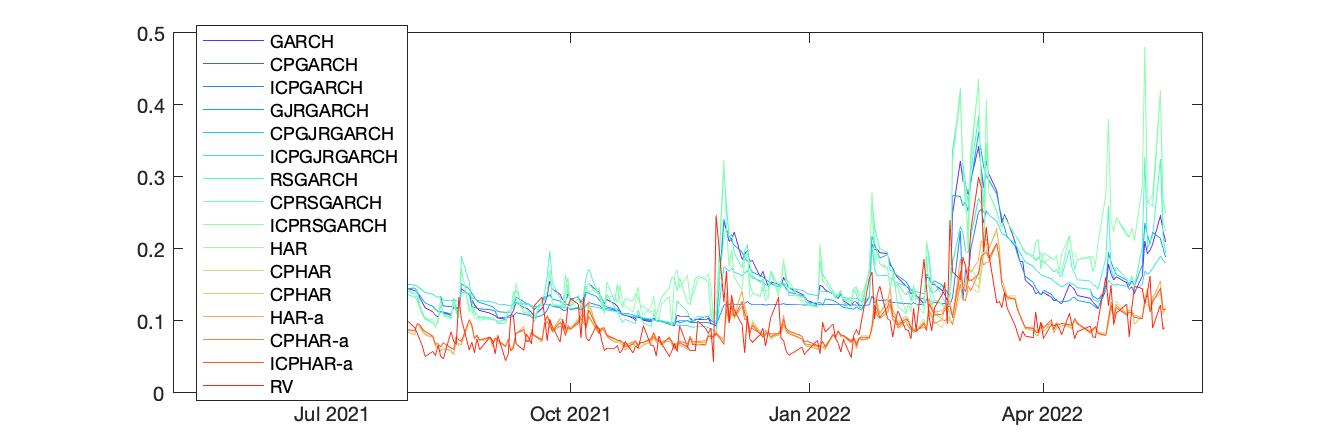

figure;
col=rainbow(16);
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(4,:));
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(5,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(6,:))
plot(Timeline_outsample,sqrt(results_RSGARCH.vf_RSGARCH)*sqrt(250), "Color",col(7,:));
plot(Timeline_outsample,sqrt(results_CPRSGARCH.vf_CPRSGARCH)*sqrt(250), "Color",col(8,:))
plot(Timeline_outsample,sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)*sqrt(250), "Color",col(9,:))
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(10,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(11,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(12,:))
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(13,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(14,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(15,:))
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(16,:))
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJRGARCH", "CPGJRGARCH", "ICPGJRGARCH", ...
    "RSGARCH", "CPRSGARCH", "ICPRSGARCH", ...
    "HAR","CPHAR","CPHAR", "HAR-a","CPHAR-a","ICPHAR-a", ...
    "RV","Location","best");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'_allmodel.png'])

Volatility forecasts: GARCH  CPGARCH, CPGARCH iteration

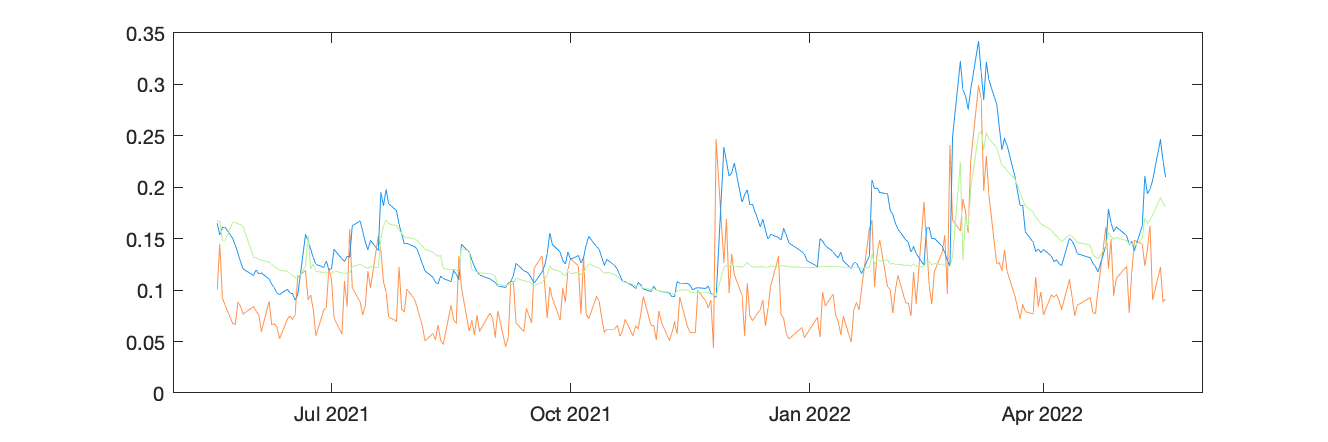

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GARCH.vf_GARCH)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGARCH.vf_CPGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGARCH.vf_ICPGARCH)*sqrt(250), "Color",col(3,:))
% legend("RV","GARCH","CPGARCH","CPGARCH Ite.");
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'garchs.png'])

Volatility forecasts: GJR, CPGJR, CPGJR iteration

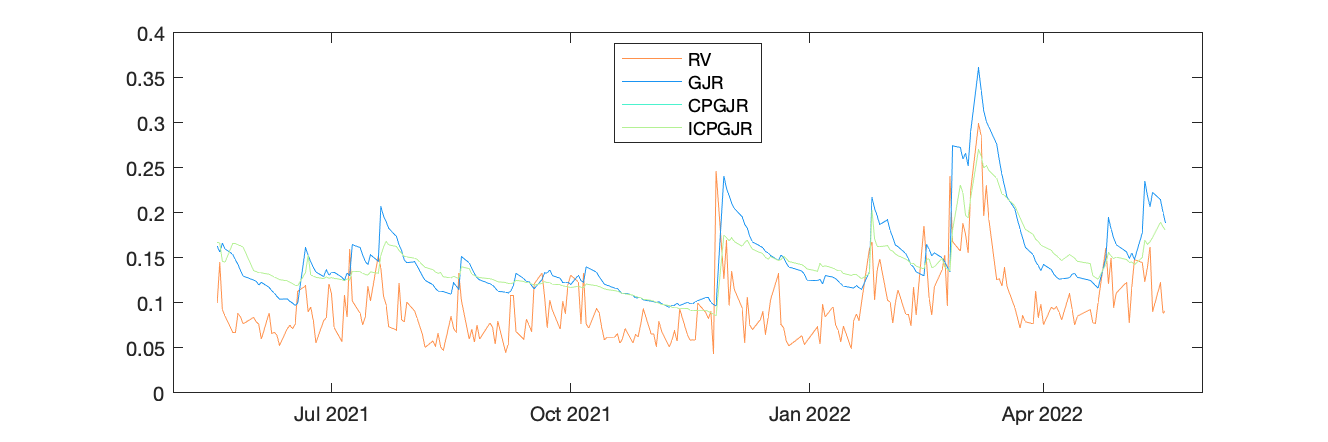

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_GJR.vf_GJR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPGJR.vf_CPGJR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPGJR.vf_ICPGJR)*sqrt(250), "Color",col(3,:))
legend("RV","GJR","CPGJR","ICPGJR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'gjrs.png'])

Volatility forecasts: RSGARCH, CPRSGARCH, CPRSGARCH iteration

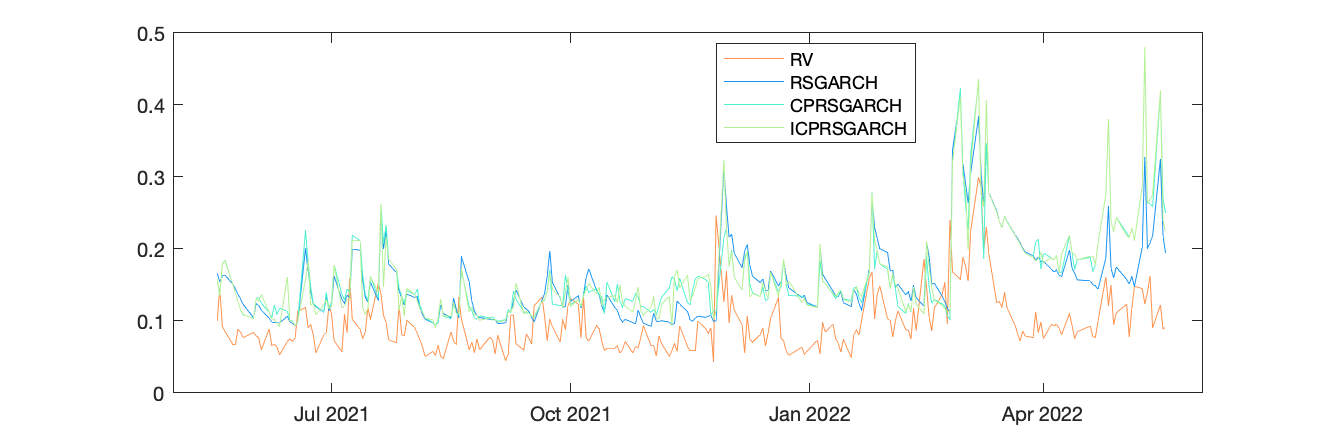

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_RSGARCH.vf_RSGARCH)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPRSGARCH.vf_CPRSGARCH)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)*sqrt(250), "Color",col(3,:))
legend("RV","RSGARCH","CPRSGARCH","ICPRSGARCH",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'rsgarchs.png'])

Volatility forecasts: HAR, CPHAR, ICPHAR

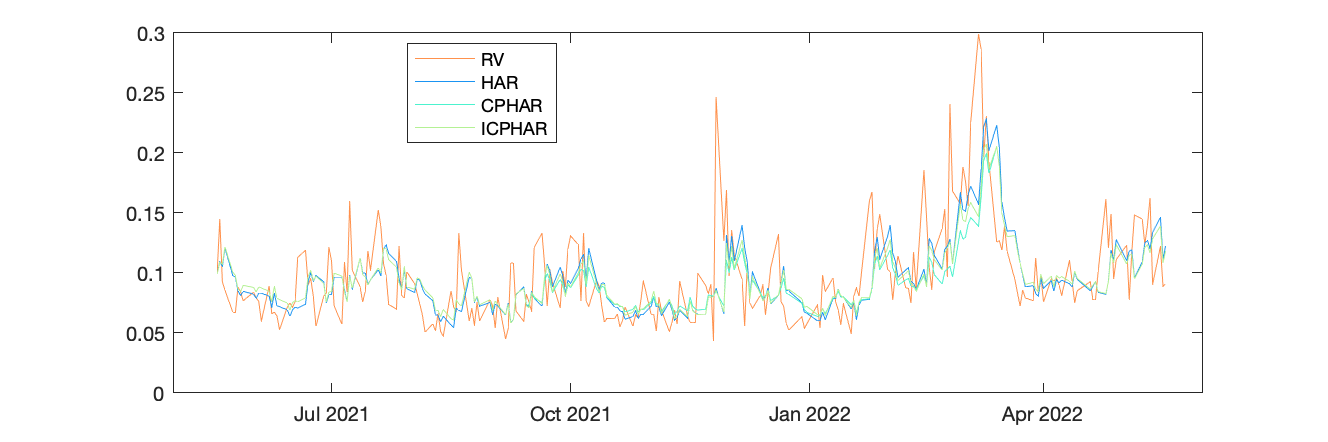

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR.vf_HAR)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR.vf_CPHAR)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR.vf_ICPHAR)*sqrt(250), "Color",col(3,:))
legend("RV","HAR","CPHAR","ICPHAR",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'hars.png'])

Volatility forecasts: HAR-a, CPHAR-a, ICPHAR-a

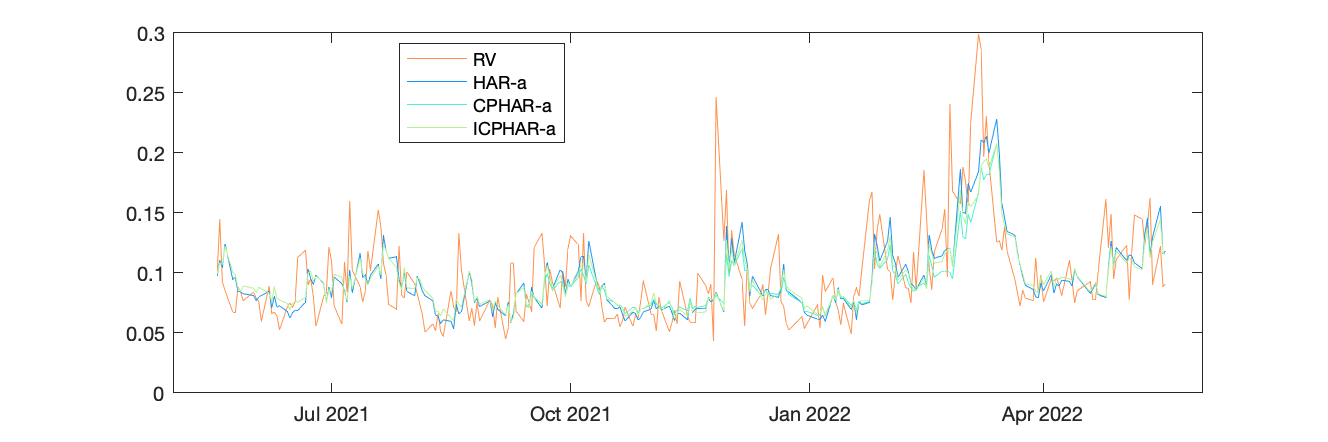

figure;
col=rainbow(4);
plot(Timeline_outsample,sqrt(rv)*sqrt(250), "Color",col(4,:));hold on
plot(Timeline_outsample,sqrt(results_HAR_a.vf_HAR_a)*sqrt(250), "Color",col(1,:))
plot(Timeline_outsample,sqrt(results_CPHAR_a.vf_CPHAR_a)*sqrt(250), "Color",col(2,:))
plot(Timeline_outsample,sqrt(results_ICPHAR_a.vf_ICPHAR_a)*sqrt(250), "Color",col(3,:))
legend("RV","HAR-a","CPHAR-a","ICPHAR-a",'Location','best');
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/volatility_forecast_',Index_Name,'haras.png'])

#### Figure of parameters in each estimation window

GARCH

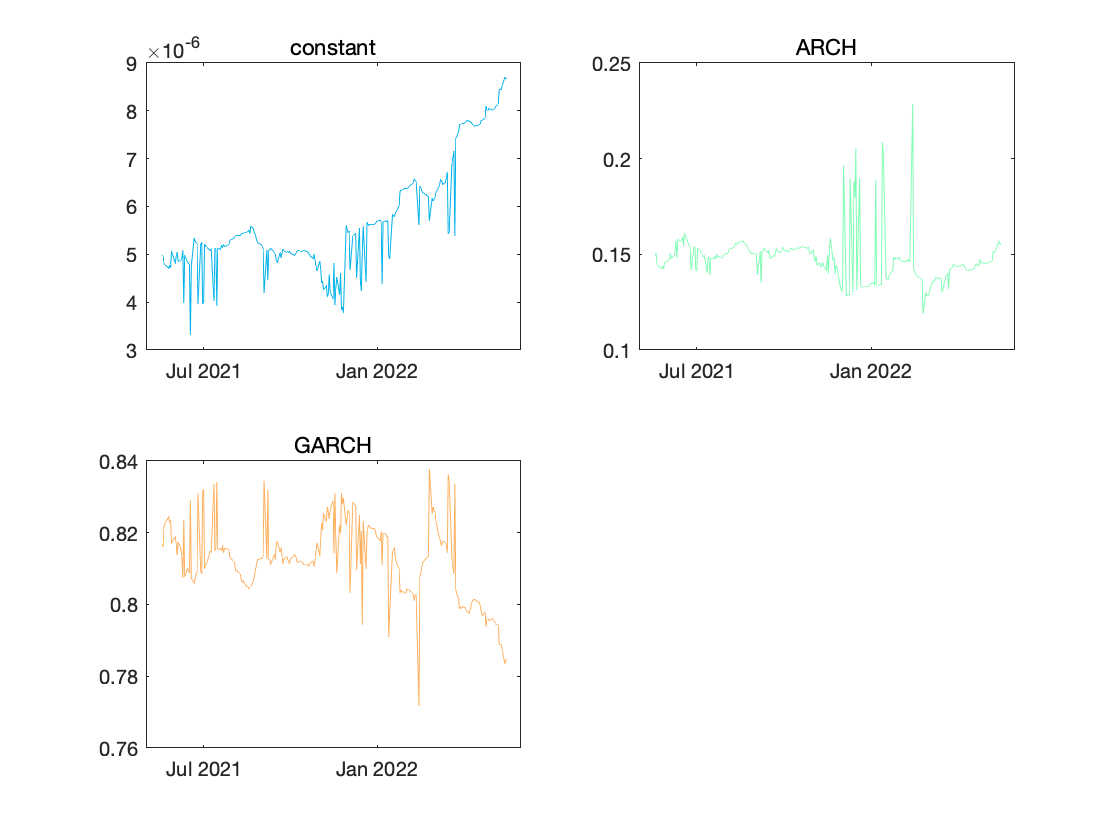

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,results_GARCH.para(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,results_GARCH.para(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,results_GARCH.para(:,3),"Color",col(3,:));
subtitle("GARCH")
saveas(gcf,[results_folder,'/dynamic_parameters_',Index_Name,'garch.png'])

#### Figure of optimal cluster number in each estimation window

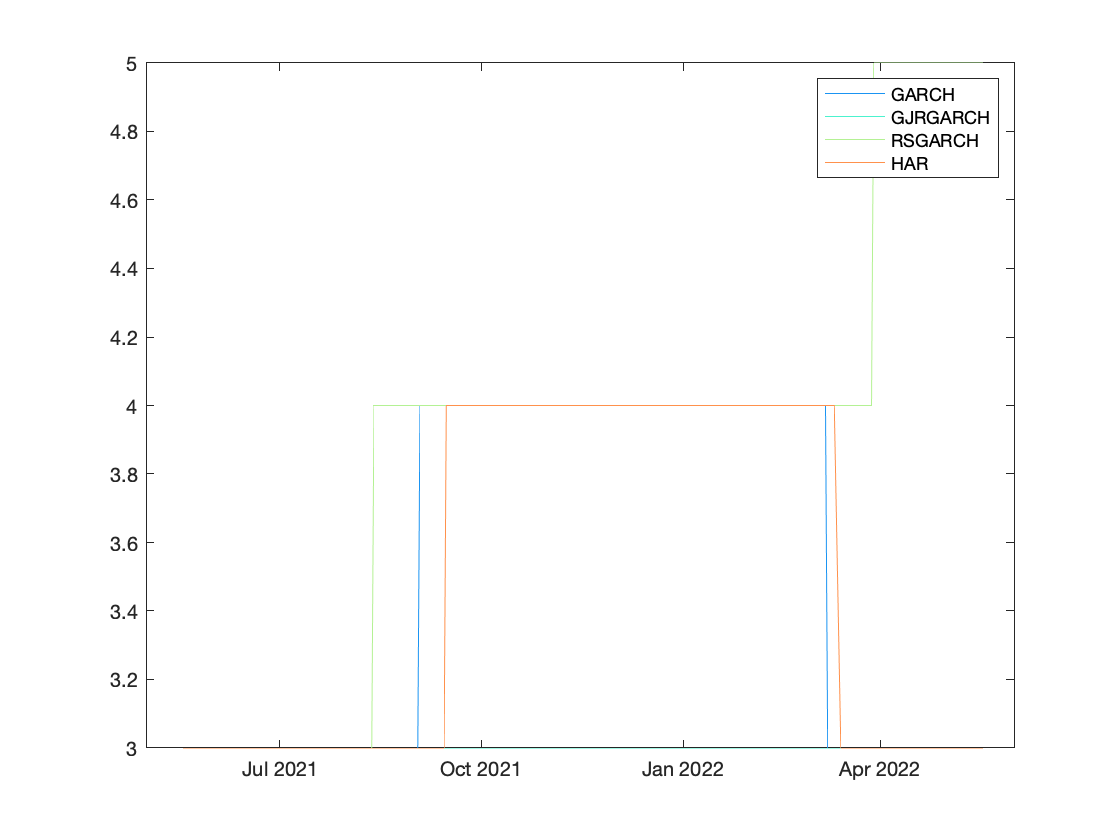

figure;
col=rainbow(4);
plot(Timeline_outsample,results_CPGARCH.K,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGJR.K,"Color",col(2,:));hold on
plot(Timeline_outsample,results_CPRSGARCH.K,"Color",col(3,:));
plot(Timeline_outsample,results_CPHAR.K,"Color",col(4,:));
plot(Timeline_outsample,results_CPHAR_a.K,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")
saveas(gcf,[results_folder,'/dynamic_optimal_cluster_number.png'])

#### Figure of in-sample MAE and MSE

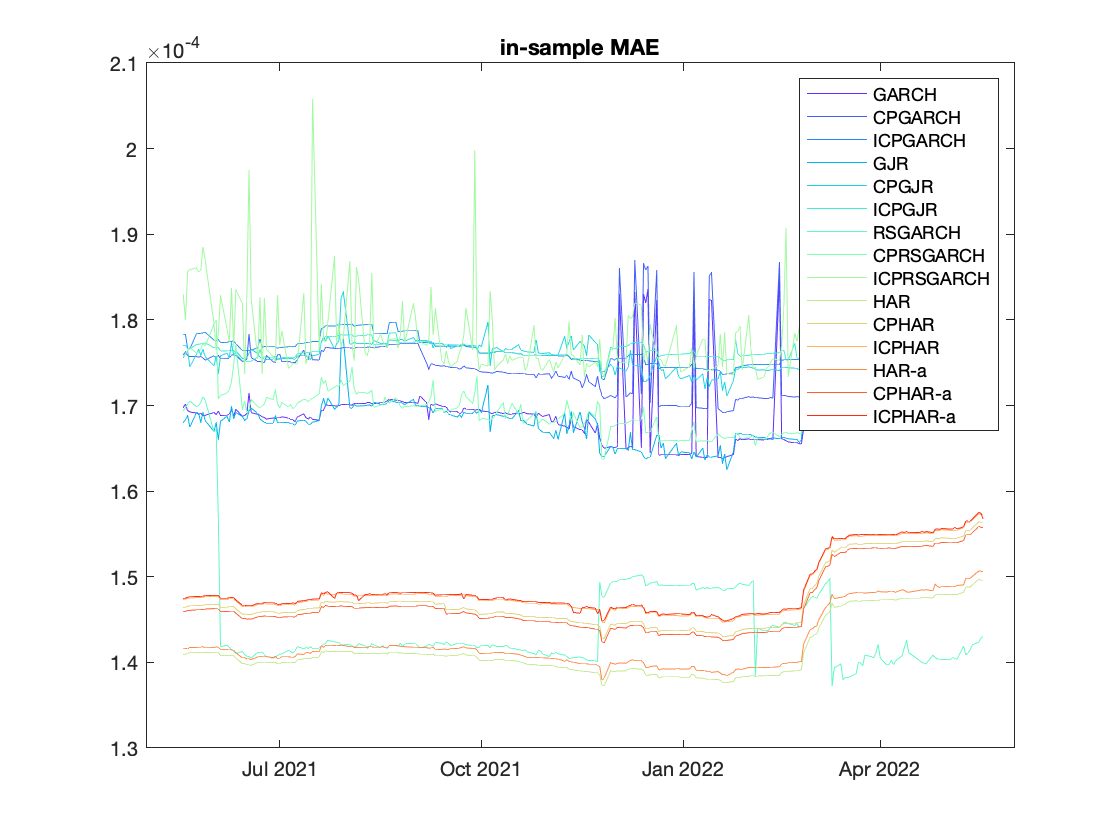

figure;
col=rainbow(15);
plot(Timeline_outsample,results_GARCH.ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.ismae_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.ismae_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_RSGARCH.ismae_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,results_CPRSGARCH.ismae_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,results_ICPRSGARCH.ismae_ICPRSGARCH,"Color",col(9,:));
plot(Timeline_outsample,results_HAR.ismae_HAR,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR.ismae_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR.ismae_ICPHAR,"Color",col(12,:));
plot(Timeline_outsample,results_HAR_a.ismae_HAR_a,"Color",col(13,:));
plot(Timeline_outsample,results_CPHAR_a.ismae_CPHAR_a,"Color",col(14,:));
plot(Timeline_outsample,results_ICPHAR_a.ismae_ICPHAR_a,"Color",col(15,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "RSGARCH","CPRSGARCH","ICPRSGARCH", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample MAE")
saveas(gcf,[results_folder,'/insample_mae.png'])

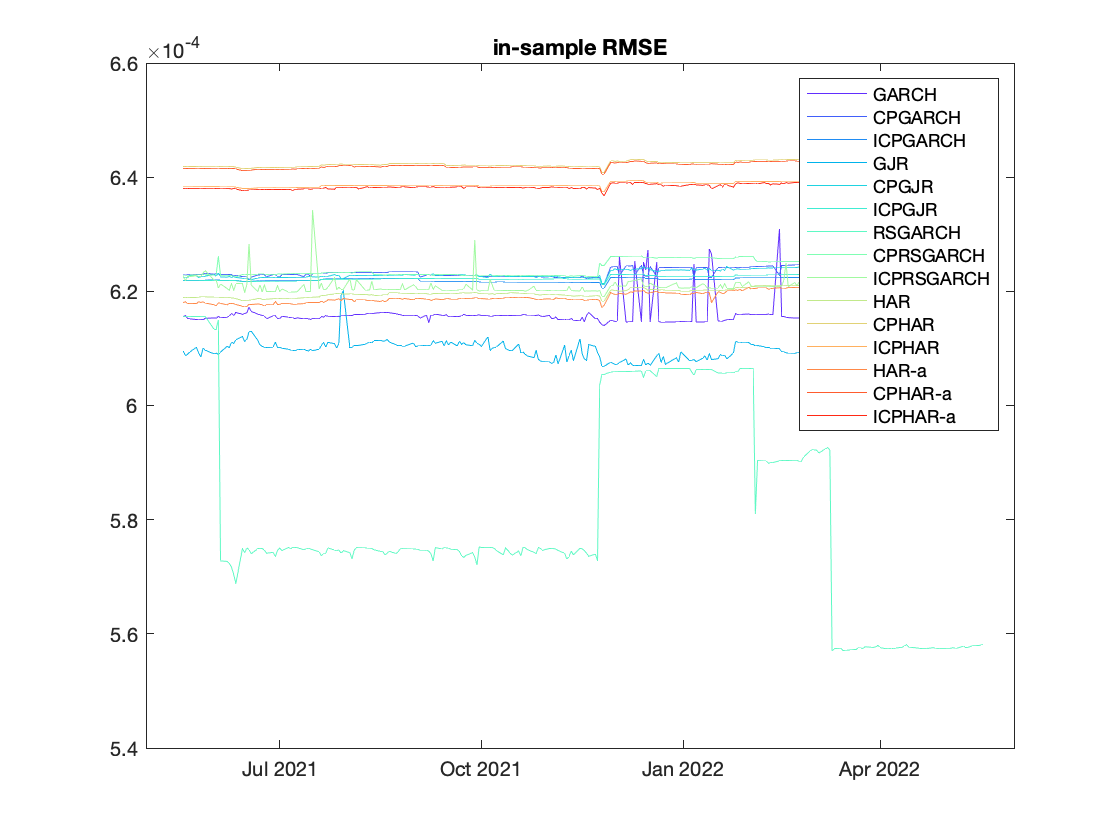

figure;
col=rainbow(15);
plot(Timeline_outsample,results_GARCH.isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,results_CPGARCH.isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,results_ICPGARCH.isrmse_ICPGARCH,"Color",col(3,:));
plot(Timeline_outsample,results_GJR.isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,results_CPGJR.isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,results_ICPGJR.isrmse_ICPGJR,"Color",col(6,:));
plot(Timeline_outsample,results_RSGARCH.isrmse_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,results_CPRSGARCH.isrmse_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,results_ICPRSGARCH.isrmse_ICPRSGARCH,"Color",col(9,:));
plot(Timeline_outsample,results_HAR.isrmse_HAR,"Color",col(10,:));
plot(Timeline_outsample,results_CPHAR.isrmse_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,results_ICPHAR.isrmse_ICPHAR,"Color",col(12,:));
plot(Timeline_outsample,results_HAR_a.isrmse_HAR_a,"Color",col(13,:));
plot(Timeline_outsample,results_CPHAR_a.isrmse_CPHAR_a,"Color",col(14,:));
plot(Timeline_outsample,results_ICPHAR_a.isrmse_ICPHAR_a,"Color",col(15,:));
legend("GARCH","CPGARCH","ICPGARCH", ...
    "GJR","CPGJR","ICPGJR", ...
    "RSGARCH","CPRSGARCH","ICPRSGARCH", ...
    "HAR","CPHAR","ICPHAR","HAR-a","CPHAR-a","ICPHAR-a")
title("in-sample RMSE")
saveas(gcf,[results_folder,'/insample_rmse.png'])

#### MAE & RMSE

MAE=[mean(abs(sqrt(results_GARCH.vf_GARCH)-sqrt(rv)));mean(abs(sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_GJR.vf_GJR)-sqrt(rv)));mean(abs(sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)));mean(abs(sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)))
    mean(abs(sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)));mean(abs(sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)));mean(abs(sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)))
    mean(abs(sqrt(results_HAR.vf_HAR)-sqrt(rv)));mean(abs(sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)))
    mean(abs(sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)));mean(abs(sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)));mean(abs(sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)))]*sqrt(250);
RMSE=sqrt([mean((sqrt(results_GARCH.vf_GARCH)-sqrt(rv)).^2);mean((sqrt(results_CPGARCH.vf_CPGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPGARCH.vf_ICPGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_GJR.vf_GJR)-sqrt(rv)).^2);mean((sqrt(results_CPGJR.vf_CPGJR)-sqrt(rv)).^2);mean((sqrt(results_ICPGJR.vf_ICPGJR)-sqrt(rv)).^2)
    mean((sqrt(results_RSGARCH.vf_RSGARCH)-sqrt(rv)).^2);mean((sqrt(results_CPRSGARCH.vf_CPRSGARCH)-sqrt(rv)).^2);mean((sqrt(results_ICPRSGARCH.vf_ICPRSGARCH)-sqrt(rv)).^2)
    mean((sqrt(results_HAR.vf_HAR)-sqrt(rv)).^2);mean((sqrt(results_CPHAR.vf_CPHAR)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR.vf_ICPHAR)-sqrt(rv)).^2) 
    mean((sqrt(results_HAR_a.vf_HAR_a)-sqrt(rv)).^2);mean((sqrt(results_CPHAR_a.vf_CPHAR_a)-sqrt(rv)).^2);mean((sqrt(results_ICPHAR_a.vf_ICPHAR_a)-sqrt(rv)).^2)])*sqrt(250);
outsample_mae_rmse_allmodel=table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','ICPGARCH',...
    'GJRGARCH','CPGJRGARCH','ICPGJRGARCH.', ...
    'RSGARCH','CPRSGARCH','ICPRSGARCH','HAR','CPHAR','ICPHAR','HAR-a','CPHAR-a','ICPHAR-a'})

outsample_mae_rmse_allmodel = 15×2 table
                      MAE         RMSE  
                    ________    ________

    GARCH            0.05595    0.064229
    CPGARCH         0.045567    0.052909
    ICPGARCH        0.045567    0.052909
    GJRGARCH        0.055924    0.063148
    CPGJRGARCH      0.051541    0.058453
    ICPGJRGARCH.    0.051541    0.058453
    RSGARCH         0.063155    0.074132
    CPRSGARCH       0.069993    0.083751
    ICPRSGARCH      0.069985    0.084347
    HAR             0.022931     0.03197
    CPHAR           0.023151    0.032835
    ICPHAR          0.022861    0.031867
    HAR-a           0.022749      0.0314
    CPHAR-a         0.022817    0.032

ftxt=fopen([results_folder,'/outsample_mae_rmse_allmodel.txt'],'w+');
table2latex(outsample_mae_rmse_allmodel,ftxt)
fclose(ftxt);

#### DM test

fcst=readtable(['Volatility_Forecast_',Working_Date,'.xlsx']);
dm_test=nan(15,15);
for i=1:15
    for j=1:15
        dm_test(i,j)=dmtest(table2array(fcst(:,i+1))-sqrt(rv),table2array(fcst(:,j+1))-sqrt(rv));
    end
end
dm_table=table(dm_test, ...
    'RowNames',{'GARCH','CPGARCH','ICPGARCH', ...
    'GJR','CPGJR','ICPGJR', ...
    'RSGARCH','CPRSGARCH','ICPRSGARCH', ...
    'HAR','CPHAR','ICPHAR', 'HAR-a','CPHAR-a','ICPHAR-a'})

dm_table = 15×1 table
                    dm_test  
                  ___________

    GARCH         1×15 double
    CPGARCH       1×15 double
    ICPGARCH      1×15 double
    GJR           1×15 double
    CPGJR         1×15 double
    ICPGJR        1×15 double
    RSGARCH       1×15 double
    CPRSGARCH     1×15 double
    ICPRSGARCH    1×15 double
    HAR           1×15 double
    CPHAR         1×15 double
    ICPHAR        1×15 double
    HAR-a         1×15 double
    CPHAR-a       1×15 double
    ICPHAR-a      1×15 double


ftxt=fopen([results_folder,'/dm_test.txt'],'w+');
table2latex(dm_table,ftxt)
fclose(ftxt);
toc

Elapsed time is 5998.961536 seconds.
